# INME 4717 - HW4

# Group 3

Lagares, Christian J.

Lopez, Jaime

Torres, Yazmin

Borgos, Giovanni

Nuñez, Wilfredo

# Introduction

Consider the design of Cessna example. The aircraft has 2-engines propeller driven engines. Assume that a preliminary wing model is that of a straight wing made of isotropic (metallic) material. 

The operating (cruise) speed at 13,000 km is Mach 0.89. The maximum take-off weight is 3,379 kg (including the engines). The dry weight of each engine is 800 kg. The one-wing analysis is such that the engines can be located as point loads at $P1 = (x,y,z) = (\frac{2b}{5},0,\frac{c}{3})$, and $P2 = (x,y,z) = (\frac{-2b}{5},0,\frac{c}{3})$. The chord is measured at the neutral axis. You are asked to analyze the wing loads about the aerodynamic center. 

The wing's distributed lift can be modeled as:


$$L(x,z) = q_{0}\sqrt{1-(\frac{x}{b})^{2}}$$


The value $q_0$ is determined by the fact that the aircraft must be save at $n_{max}=7.0$ (maximum load factor. Assume that the drag is:

 
$$D(x) = p_{0}\sqrt{1-(\frac{x}{b})^{2}}$$


where $p_{0} = \frac{q_{0}}{5}$. Determine the exact load diagrams and the discretized load diagram.

# General Properties

The general properties of the problem will be stated in this section. These include, maximum loading parameters, lengths of the sections and other relevant information.

clear; clc;
format('longE')
n = 7;
WingSpan   = 493.500;    % in
WingLength = WingSpan/2; % in
WingArea   = 30960;      % in^2
Weight     = 7449.42;    % lb
Altitude   = 511811000;  % in
Mach       = 0.89;       
Velocity   = 1001.542;   % ft/s

[b1, b2, b3, b4, b5, b6, chord] = LinearNACA0012(); % in

# Problem 1

## Introduction

In this section, an analytical solution for the described problem will be developed. Where numerical coefficients are explicitly defined, the authors will procede to collapse their related numerical values into a single constant. This section will make extensive use of the ***Symbolic Math Toolbox***.

The ***Symbolic Math Toolbox*** contains a function called `sym()`which has the following syntax in the context of a problem:

`x = sym('x');`

This statement, in the context of a program, implies the analytical variable 'x' is stored in the memory pointer `x`. Every subsequent operation involving `x` is treated as a symbolic operation. 

## Analytical Development

The following code yields the analytical equivalent to the following expression:


$$L(x,z) = q_0\, \sqrt{1 - \frac{16\, x^2}{974169}} [lb]$$


   
$$D(x) = \frac{q_0}{5}\, \sqrt{1 - \frac{16\, x^2}{974169}} [lb]$$


q0 = sym('q0');
p0 = q0/5;
b  = WingLength;
x  = sym('x');
y  = sym('y');
z  = sym('z');
L  = q0*sqrt(1-(x./b).^2);
D  = -p0*sqrt(1-(x./b).^2);

The lift is now represented by a 2D distributed load, although it is symetric with respect to the z axis. The lift equation is integrated with respect to *z* in order to *"collapse"* it to the x axis. The analytical process can be simplified as follows:


$$L= \int_0^{b} \int_0^c q_{0}\sqrt{1-(\frac{x}{b})^{2}} dz~dx$$
 

where b is equal to half the wing span. This integral, when equating b to the actual numerical value, results in the following expression:


$$L_{wing}=\frac{4357232639377123023\, \pi\, \mathrm{q0}}{1125899906842624}$$


Given the symetry of the lift, the resulting expression can be multiplied by 2 in order to obtain the total lift force for the entirety of the wingspan.

Lx = 2*int(int(L,z,[0,chord]),x,[0,b]);

The resulting lift in terms of $q_0$:


$$L_{wingspan} = \frac{4357232639377123023\, \pi\, \mathrm{q0}}{562949953421312}$$


This constant can be determined knowing the $L$ is related to $n$ as:


$$n = \frac{L}{W}$$


Therefore the following expression is also true,


$$n*W=\frac{4357232639377123023\, \pi\, \mathrm{q0}}{562949953421312}$$


where the only unknown is $q_0$. 


$$q_o=\frac{21747994806779452771410501926865}{10141204801825835211973625643008}\approx 2.1445$$


q0 = sym((n*Weight)/pi)*sym(562949953421312/4357232639377123023);
p0 = q0/5;
L  = q0*sqrt(1-(x./b).^2);
Dx = -p0*sqrt(1-(x./b).^2);
Lx = int(L,z,[0,chord]);


$$L(x) = \frac{32003064104391624328223510025852288215920855695\, \sqrt{974169 - 16\, x^2}}{234782245450130400434088041974441949934961819648} \approx 0.1363\sqrt{974169 - 16\, x^2}$$


In order to provide a 3D visualization of the lift force, a matrix must be assembled resembling a surface of values for the lift at a particular coordinate along the Wingspan and Chord. The `resolution` parameter in the code allows for variable resolution in the computation of the Lift and Drag profiles. However, the amount of graphical, numerical and memory power required increases dramatically with an increase in resolution. The recommended resolution for low latency and reasonable accuracy is between 100 and 1000. A resolution of 10 can be used in low power environments with a reasonable output.

The default resolution for the script is 100 which should provide the best quality to speed ratio on any modern computer. The best resolution however can be obtained at 1000. Any increase above that threshold results in a barely noticeable improvement.

resolution = 100;

WingCoor   = linspace(-WingLength,WingLength,resolution);
ChordCoor  = linspace((0.125+0.5*(0.7-0.125)),(0.125+0.5*(0.7-0.125)),resolution);
LiftEq     = matlabFunction(Lx);
DragEq     = matlabFunction(Dx);
Lift       = LiftEq(WingCoor);
Drag       = DragEq(WingCoor);
LiftProf   = zeros(resolution);
DragProf   = zeros(resolution);
for ii = 1:resolution
    LiftProf(ii,:) = Lift;
    DragProf(ii,:) = Drag;
end

The lift force can be visualized as:

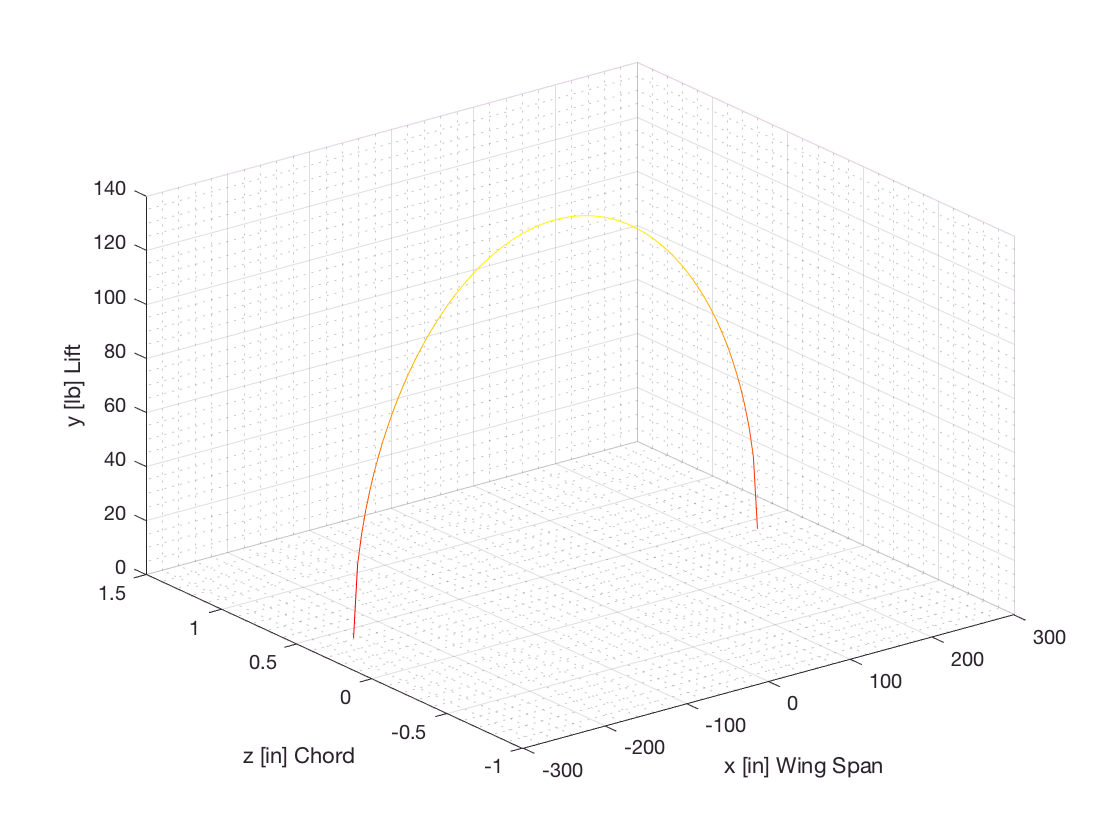

figure('Name','Theoretical Lift')
mesh(WingCoor,ChordCoor,LiftProf)
xlabel('x [in] Wing Span')
ylabel('z [in] Chord')
zlabel('y [lb] Lift')
grid on 
grid minor
colormap('autumn')

The drag force can be visualized as:

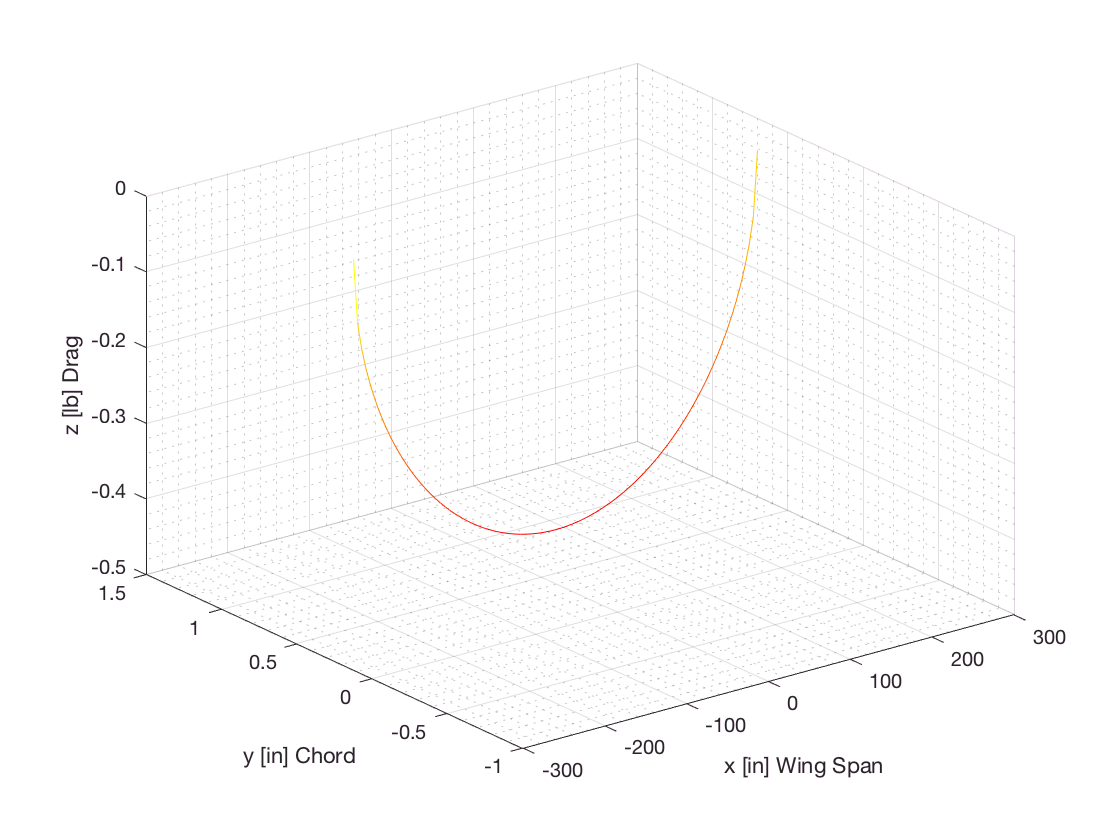

figure('Name','Theoretical Drag')
mesh(WingCoor,ChordCoor,DragProf)
xlabel('x [in] Wing Span')
ylabel('y [in] Chord')
zlabel('z [lb] Drag')
grid on 
grid minor
colormap('autumn')

This expression represents the physical lift force with respect to the center of the linear upper section of the wing box (or airfoil). Recall, that the airfoil for this Cessna expample is being modelled as a NACA0012 airfoil with a linearized portion in the upper and bottom sections.

From the course textbook, it is known 

*"from literature, both experimentally and analytically, if the aerodynamic force is applied at a location 1/4 chord back from the leading edge of most low-speed airfoils, the mag- nitude of the aerodynamic moment remains nearly constant with respect to the angle of attack." (Goyal et al)*

Following this general tendency, it will be assumed that the aerodynamic center in this problem is located at 1/4 of the chord length for the linearized NACA 0012 being studied. 

ac = chord/4; % aerodynamic center

The lift force will be relocated to the aerodynamic center which results in both a distributed lift force and a distributed moment (in order to compensate the force's displacement).

The first step is to locate the reference coordinate system and compute a linear transformation of this system. In order to facilitate the analysis, the reference system will be located at the leading edge of the airfoil. The convenient placement of the coordinate system at this location will allow for non-negative quantities being transformed to the aerodynamic center-based reference system.

acAxis = ac-(0.125.*chord); % shift the reference y-axis

The distributed lift load is originally located at the center of the horizontal section of the linearized NACA 0012 being analyzed. The following section will calculate the initial and aerodynamic center-based load location.

L_originalLocation = (0.125*chord)+(0.5*0.45*chord);
L_acLocation       = L_originalLocation-ac;

In order to translate the lift force to the aerodynamic center-based, a distributed moment must be added in order to account for the resulting effect.


$$M(x) = L(x)*d$$


where `d` is represented in the script as `L_acLocation`. This can be incorporated analytically as:


$$M(x) = \frac{56512581753083498950734134615006079186609548808188723510686245\, \sqrt{974169 - 16\, x^2}}{66085327070150975081663191047530312028725598119317355351769088}\approx 0.8551\sqrt{974169 - 16\, x^2} [lb- in]$$


Mx = Lx*L_acLocation;

The set of forces with respect to the aerodynamic center can be expressed as:


$$L(x)\approx 0.1363\sqrt{974169 - 16\, x^2}~[lb]\\
M(x)\approx 0.8551\sqrt{974169 - 16\, x^2}  [lb- in]\\
D(x)\approx-0.4289\sqrt{1 - \frac{16\, x^2}{974169}} ~~~~~[lb]$$


where $L(x)$ acts updwardly on the y axis, $D(x)$ acts horizontally along the z axis and $M(x)$ acts along the x axis.

Now, the pair of concentrated loads for the engines must be mathematically translated to the aerodynamic center in order to procede with the analysis. Recall the location where the engines are located as:


$$P1(x = \frac{2b}{5}, y =0, z=\frac{c}{3}) = 1,763.7~~[lb]\\
P2(x = \frac{-2b}{5}, y =0, z=\frac{c}{3}) = 1,763.7~[lb]\\$$


This pair of concentrated loads act downwardly along the z-axis. Note that they are located originally at $\frac{1}{3}$ the length of the chord and must be translated to $\frac{1}{4}$ the length of the chord in order to analyze the system with respect to the aerodynamic center. The distance from the original location to the aerodynamic center is calculated as:


$$\frac{\Delta d}{c} = \frac{1}{3}-\frac{1}{4} =\frac{4}{12}-\frac{3}{12} =\frac{1}{12}\\

\Delta d = \frac{c}{12} \approx 5.2280~[in]$$


Engine_ac = chord/12;

Therefore, the engine loads and moments can be expressed as:

P1  = -1763.7;       % lb
P2  = -1763.7;       % lb
MP1 = P1*Engine_ac; % lb-in
MP2 = P2*Engine_ac; % lb-in

Now, the full set of forces acting on the aerodynamic center can be expressed in the following set of equations:


$$L(x)\approx 0.1363\sqrt{974169 - 16\, x^2}~[lb]\\
M(x)\approx 0.8551\sqrt{974169 - 16\, x^2}  [lb- in]\\
D(x)\approx-0.4289\sqrt{1 - \frac{16\, x^2}{974169}} ~~~~~[lb]\\
P_1(\frac{2b}{5}, 0, \frac{c}{3}) = -1,763.7~~~~~~~~~~[lb]\\
P_2(\frac{-2b}{5}, 0, \frac{c}{3}) = -1,763.7~~~~~~~~~[lb]\\
M_1(\frac{2b}{5}, 0, \frac{c}{3})\approx-9,220.6~~~~~~~~~~[lb-in] \\
M_2(\frac{-2b}{5}, 0, \frac{c}{3}) \approx-9,220.6~~~~~~~~~[lb-in] \\$$


Given this set of equations, the shear and moment diagrams for half the wingspan can be computed and can be generalized through symetry to the opposite half.

The reactions along the x axis are determined through the following set of equaitons:


$$\Sigma F_{x} = 0 \to -N_{xxR}+\int_0^b{p_{x}(\psi)d\psi}=0\\

\Sigma M_{x} = 0 \to  -M_{xxR}+(\int_0^b{m_{x}(\psi)d\psi}+M_{1})=0\\$$


which yield the following result:


$$\Sigma F_{x} = 0 \to -N_{xxR}+\int_0^b{p_{x}(\psi)d\psi}=0\\
~~~~~~~\to ~~N_{xxR} = 0\\

\Sigma M_{x} = 0 \to  -M_{xxR}+(\int_0^b{m_{x}(\psi)d\psi}+M_{1})=0\\
~~~~~~~ \to M_{xxR} = \int_0^b{m_{x}(\psi)d\psi}+M_{1}\\
~~~~~~~ \to M_{xxR} = \int_0^b{0.8551\sqrt{974169 - 16\, \psi^2} d\psi-9220.6}\\
~~~~~~~ \to M_{xxR}  \approx 172790.80267 ~[lb-in]$$


NxxR = 0;
MxxR = int(Mx,x,[0,b])-MP1;


$$\Sigma F_{y} = 0 \to -V_{yR}+\int_0^b{p_{y}(\psi)d\psi}=0\\
~~~~~~~\to ~~V_{yR} = \int_0^b{p_{y}(\psi)d\psi}\\
~~~~~~~\to ~~V_{yR} = \int_0^b{L(\psi)d\psi}\\
~~~~~~~\to ~~V_{yR} = \int_0^b{0.1363\sqrt{974169 - 16\, \psi^2}d\psi}-1763.7\\
~~~~~~~\to ~~V_{yR} \approx 24309~[lb] \\


\Sigma M_{y} = 0 \to  -M_{yyR}+\int_0^b{\{m_{x}(\psi)-\int_0^\psi D(\beta)d\beta\}d\psi}=0\\
~~~~~~~ \to M_{yyR} = -\int_0^b{\int_0^\psi D(\beta)d\beta ~d\psi}\\
~~~~~~~ \to M_{yyR} \approx 11805~[lb-in] \\$$


VyR  = int(Lx,x,[0,b])+P1;
MyyR = -int(int(Dx,[0,x]),x,[0,b]);


$$\Sigma F_{z} = 0 \to -V_{zR}+\int_0^b{p_{z}(\psi)d\psi}=0\\
~~~~~~~\to ~~V_{zR} = \int_0^b{p_{z}(\psi)d\psi}\\
~~~~~~~\to ~~V_{zR} = \int_0^b{D(\psi)d\psi}\\
~~~~~~~\to ~~V_{zR} = \int_0^b{-0.4289\sqrt{1 - \frac{16\, \psi^2}{974169}}d\psi}\\
~~~~~~~\to ~~V_{zR} \approx -83.1202~[lb] \\


\Sigma M_{z} = 0 \to  -M_{zzR}+\int_0^b{\{m_{z}(\psi)+\int_0^\psi L(\beta)d\beta\}d\psi}+M_z=0\\
~~~~~~~ \to M_{zzR} = \int_0^b{\int_0^\psi L(\beta)d\beta d\psi}+M_z\\
~~~~~~~ \to M_{zzR} \approx 3877118.06427~[lb-in] \\$$


VzR  = int(Dx,x,[0,b]);
MzzR = int(int(Lx,[0,x]),x,[0,b])-P1*(2*b)/5;

# Problem 2

## Equations and Evaluation

After determining the reactions at the tip of the wing, the shear, moment diagrams can be determined. The process employs the same equations previously seen with the integration made from zero to an arbitrary point along the integration path.

Determine $N_{xx}$:

Nxx = NxxR - 0; 
Nxx = zeros(1,resolution);

Determine $M_{xx}$:

Mxx1 = MxxR - (int(Mx,x,[0,x])); 
Mxx1 = matlabFunction(Mxx1); 
Mxx2 = MxxR - (int(Mx,x,[0,x])-MP1); 
Mxx2 = matlabFunction(Mxx2); 
xMMxx = [linspace(0,2*WingLength/5,2*resolution/5),linspace(2*WingLength/5,WingLength,3*resolution/5)];
Mxx = zeros(1,resolution);
Mxx(1:2*resolution/5) = Mxx1(linspace(0,2*WingLength/5,2*resolution/5));
Mxx(1+2*resolution/5:resolution) = Mxx2(linspace(2*WingLength/5,WingLength,3*resolution/5));

Determine $V_{y}$:

xVy = [linspace(0,2*WingLength/5,2*resolution/5),linspace(2*WingLength/5,WingLength,3*resolution/5)];
Vy1 = VyR - (int(Lx,x,[0,x])); Vy1_Sym = Vy1;
Vy1 = matlabFunction(Vy1);
Vy2 = VyR - (int(Lx,x,[0,x])+P1); Vy2_Sym = Vy2;
Vy2 = matlabFunction(Vy2); 
Vy  = zeros(1,resolution);
Vy(1:2*resolution/5) = Vy1(linspace(0,2*WingLength/5,2*resolution/5));
Vy(1+2*resolution/5:resolution) = Vy2(linspace(2*WingLength/5,WingLength,3*resolution/5));

Determine $M_{yy}$:

Myy = MyyR - (-int(int(Dx,[0,x]),x,[0,x])); Myy_Sym = Myy;
Myy = matlabFunction(Myy); 
Myy = Myy(linspace(0,WingLength,resolution));

Determine $V_z$:

Vz  = VzR - (int(Dx,x,[0,x])); Vz_Sym = Vz;
Vz = matlabFunction(Vz); 
Vz = Vz(linspace(0,WingLength,resolution));

Determine $M_{zz}$:

Mzz1 = (MzzR - (int(int(Lx,[0,x]),x,[0,x]))); Mzz1_Sym = Mzz1;
Mzz1 = matlabFunction(Mzz1); 
Mzz2 = (MzzR - (int(int(Lx,[0,x]),x,[0,x]))+P1*(2*b)/5); Mzz2_Sym = Mzz2;
Mzz2 = matlabFunction(Mzz2); 
xMMzz = [linspace(0,2*WingLength/5,2*resolution/5),linspace(2*WingLength/5,WingLength,3*resolution/5)];
Mzz = zeros(1,resolution);
Mzz(1:2*resolution/5) = Mzz1(linspace(0,2*WingLength/5,2*resolution/5));
Mzz(1+2*resolution/5:resolution) = Mzz2(linspace(2*WingLength/5,WingLength,3*resolution/5));

## V-M Diagram [x]

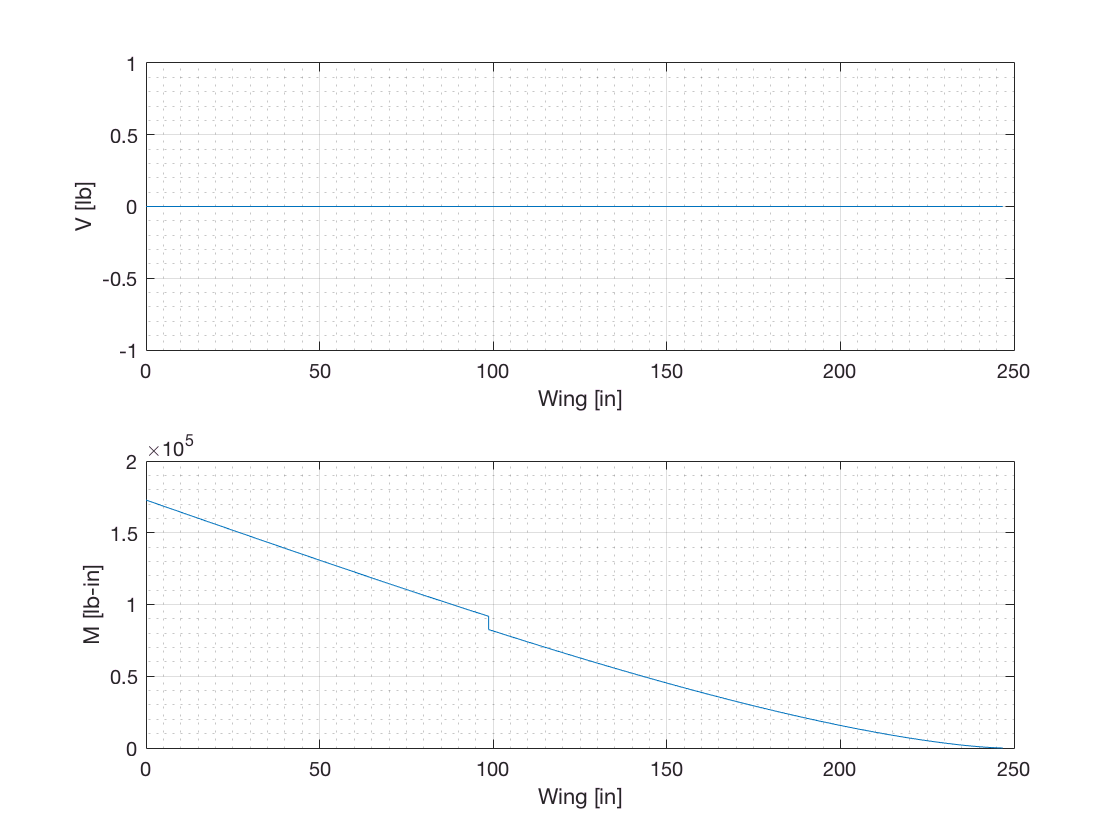

figure('Name','V-M [x]')
subplot(2,1,1)
plot(linspace(0,WingLength,resolution),Nxx)
xlabel('Wing [in]')
ylabel('V [lb]')
grid on
grid minor
subplot(2,1,2)
plot(xMMxx,Mxx)
xlabel('Wing [in]')
ylabel('M [lb-in]')
grid on
grid minor

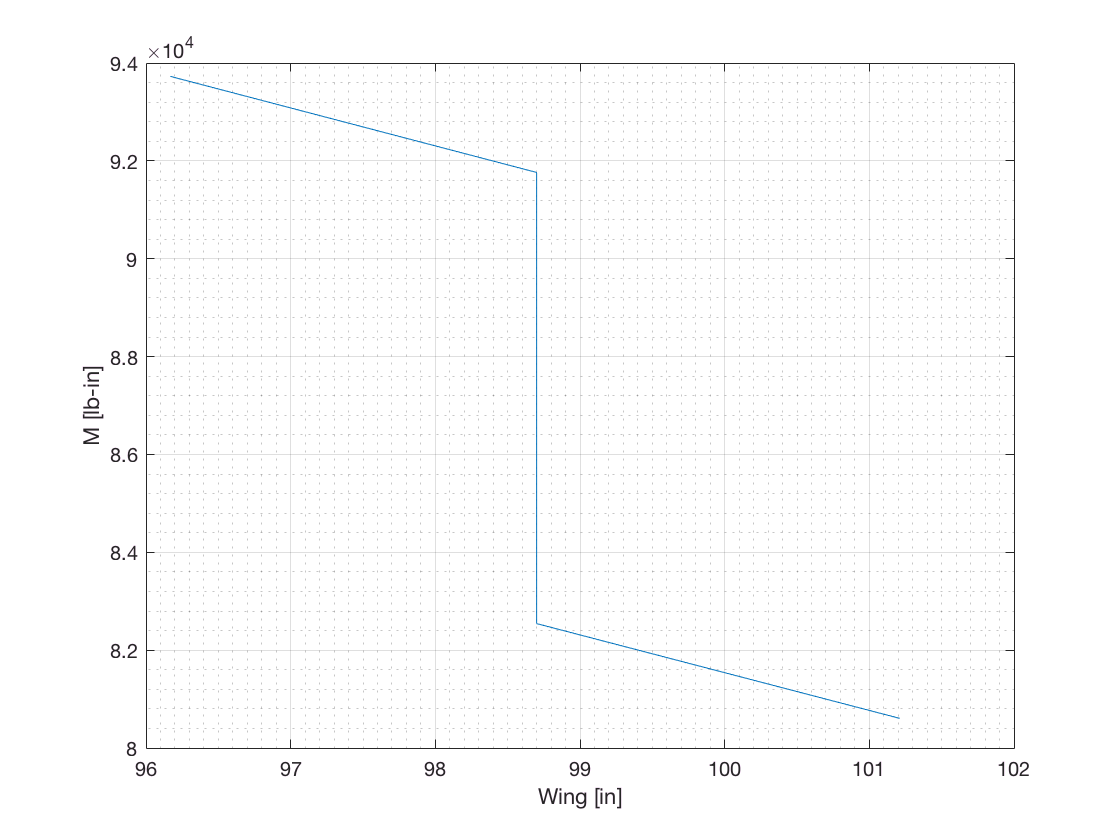

figure('Name','V-M [x] ZOOM')
plot(xMMxx(39*resolution/100:42*resolution/100),Mxx(39*resolution/100:42*resolution/100))
xlabel('Wing [in]')
ylabel('M [lb-in]')
grid on
grid minor

## V-M Diagram [y]

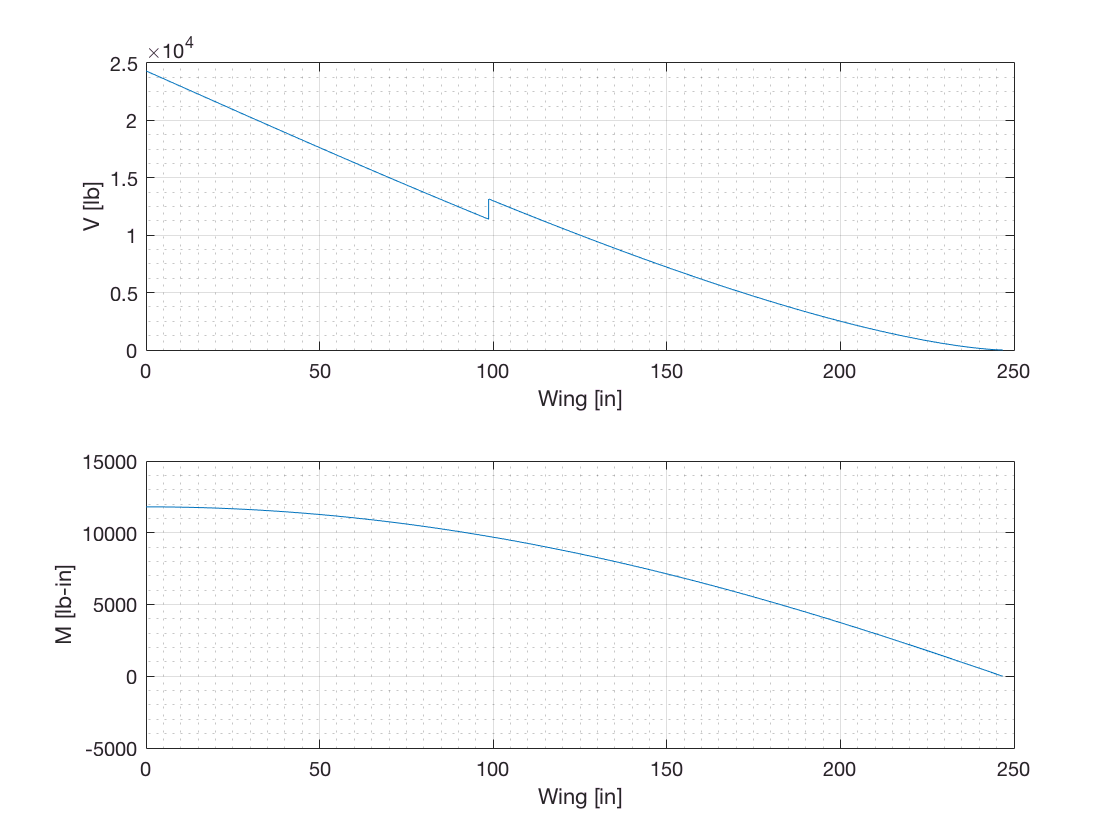

figure('Name','V-M [y]')
subplot(2,1,1)
plot(xVy,Vy)
xlabel('Wing [in]')
ylabel('V [lb]')
grid on
grid minor
subplot(2,1,2)
plot(linspace(0,WingLength,resolution),Myy)
xlabel('Wing [in]')
ylabel('M [lb-in]')
grid on
grid minor

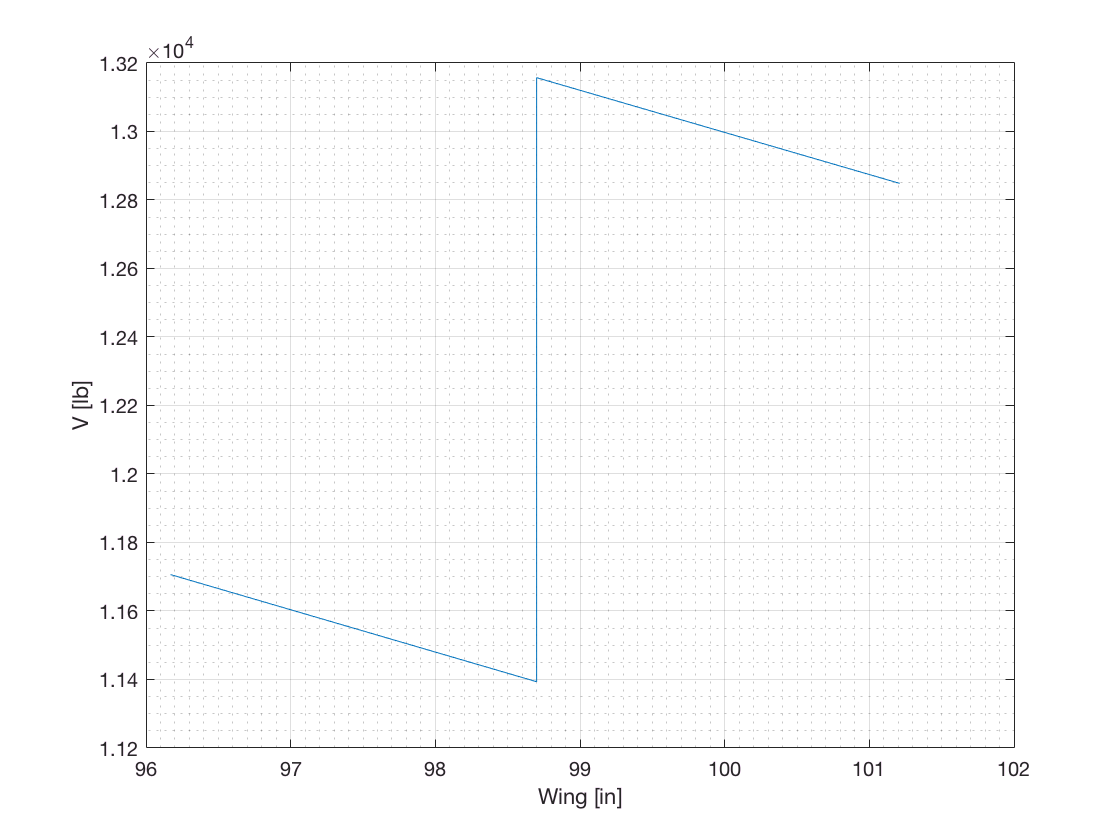

figure('Name','V-M [y] ZOOM')
plot(xVy(39*resolution/100:42*resolution/100),Vy(39*resolution/100:42*resolution/100))
xlabel('Wing [in]')
ylabel('V [lb]')
grid on
grid minor

## V-M Diagram [z]

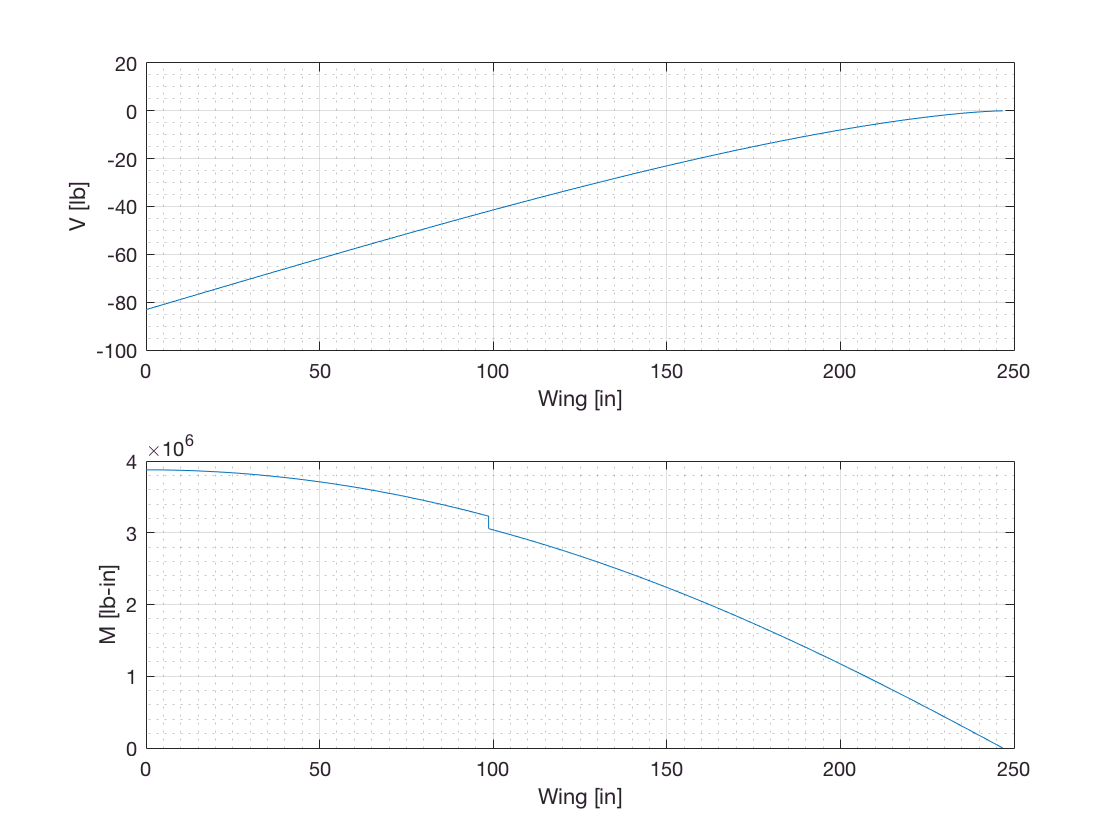

figure('Name','V-M [z]')
subplot(2,1,1)
plot(linspace(0,WingLength,resolution),Vz)
xlabel('Wing [in]')
ylabel('V [lb]')
grid on
grid minor
subplot(2,1,2)
plot(xMMzz,Mzz)
xlabel('Wing [in]')
ylabel('M [lb-in]')
grid on
grid minor

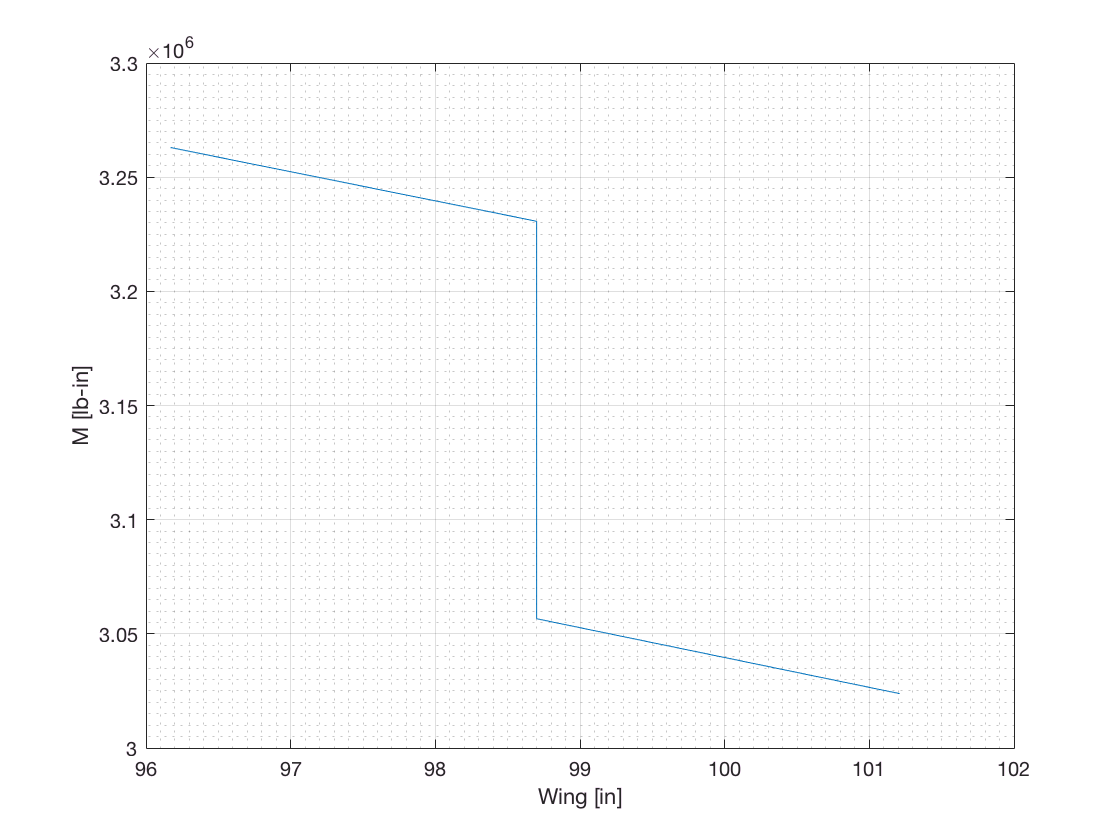

figure('Name','V-M [z] ZOOM')
plot(xMMzz(39*resolution/100:42*resolution/100),Mzz(39*resolution/100:42*resolution/100))
xlabel('Wing [in]')
ylabel('M [lb-in]')
grid on
grid minor

# Problem 3

## Discrete Solution

A solution will be be developed for 5, 10, 20 and 50 discrete points along the wing. The first step is to discretize the wing which is done in the following segment,

%%%%%%% 5-Discrete Points %%%%%%%
x5  = linspace(0, WingLength, 5);
%%%%%% 10-Discrete Points %%%%%%%
x10 = linspace(0, WingLength, 10);
%%%%%% 20-Discrete Points %%%%%%%
x20 = linspace(0, WingLength, 20);
%%%%%% 50-Discrete Points %%%%%%%
x50 = linspace(0, WingLength, 50);

The lift and drag equations are assumed to be identical to the equations employed in the anlytical derivation:


$$L(x,z) = q_{0}\sqrt{1-(\frac{x}{b})^{2}}\\
D(x) = \frac{-q_0}{5}\, \sqrt{1 - (\frac{x}{b})^{2}}$$


q0 = sym('q0');
p0 = q0/5;
b  = WingLength;
x  = sym('x');
z  = sym('z');
L_q0  = @(z,x) sqrt(1-(x./b).^2);
D_p0  = @(x)  -sqrt(1-(x./b).^2);

The lift is now represented by a 2D distributed load, although it is symetric with respect to the z axis. The lift equation is integrated with respect to *z* in order to *"collapse"* it to the x axis. 


$$\frac{L}{q_{0}}= \int_{-b}^{b} \int_0^c \sqrt{1-(\frac{x}{b})^{2}} dz~dx$$
 

This equation is solved numerically using the `integral2` numerical double integration subroutine. 

inteL_q0 = integral2(L_q0,0,chord,-b,b);

`inteL_q0` can be used in the determination of $q_0$ through the following procedure:


$$n = \frac{L}{W}\\

n = \frac{q_0*inteL\_q0}{W}\\

\frac{nW}{inteL\_q0} = q_0\\$$


q0 = (n*Weight)/inteL_q0;
p0 = q0/5;

The lift and drag profiles are discretized in the following arrays:

Lx5  = chord.*q0.*sqrt(1-(x5./b).^2);
Dx5  = chord.*-p0.*sqrt(1-(x5./b).^2);
Lx10 = chord.*q0.*sqrt(1-(x10./b).^2);
Dx10 = chord.*-p0.*sqrt(1-(x10./b).^2);
Lx20 = chord.*q0.*sqrt(1-(x20./b).^2);
Dx20 = chord.*-p0.*sqrt(1-(x20./b).^2);
Lx50 = chord.*q0.*sqrt(1-(x50./b).^2);
Dx50 = chord.*-p0.*sqrt(1-(x50./b).^2);

The effect of a coarser discretization can be seen in the following lift and drag diagrams.

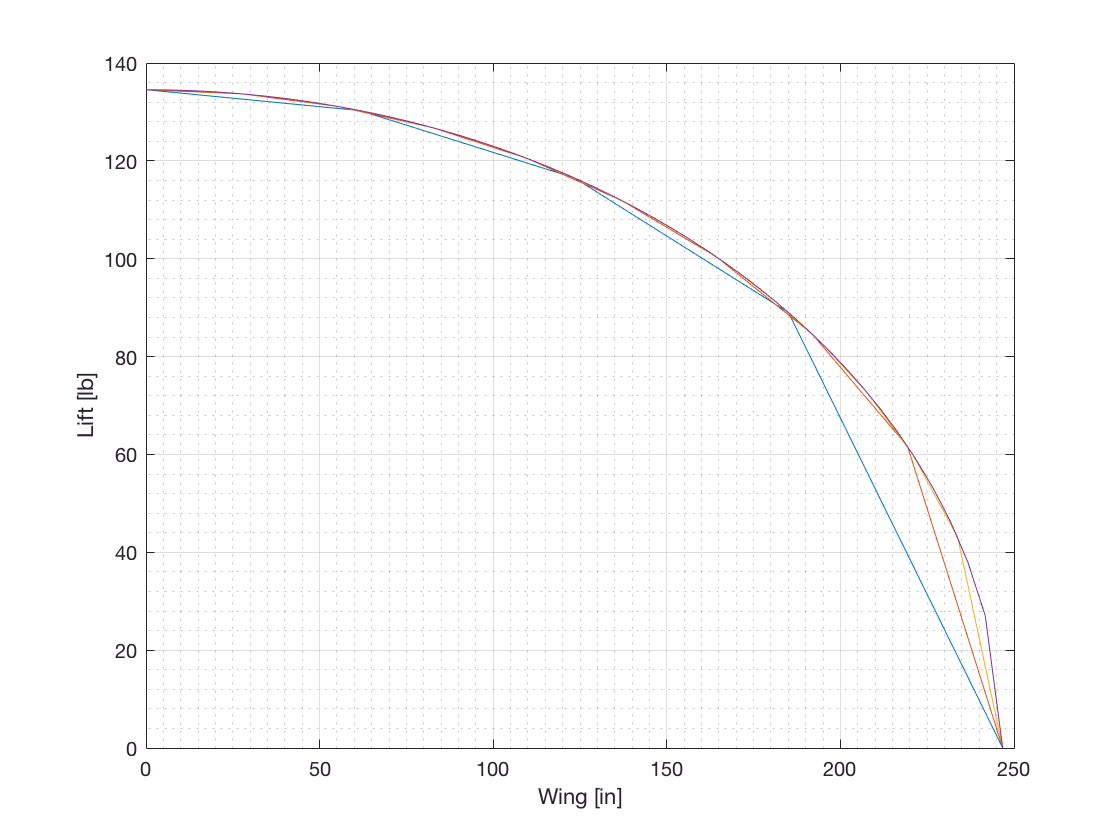

figure('Name','Discrete Lift Diagram')
plot(x5,Lx5,x10,Lx10,x20,Lx20,x50,Lx50)
xlabel('Wing [in]')
ylabel('Lift [lb]')
grid on
grid minor

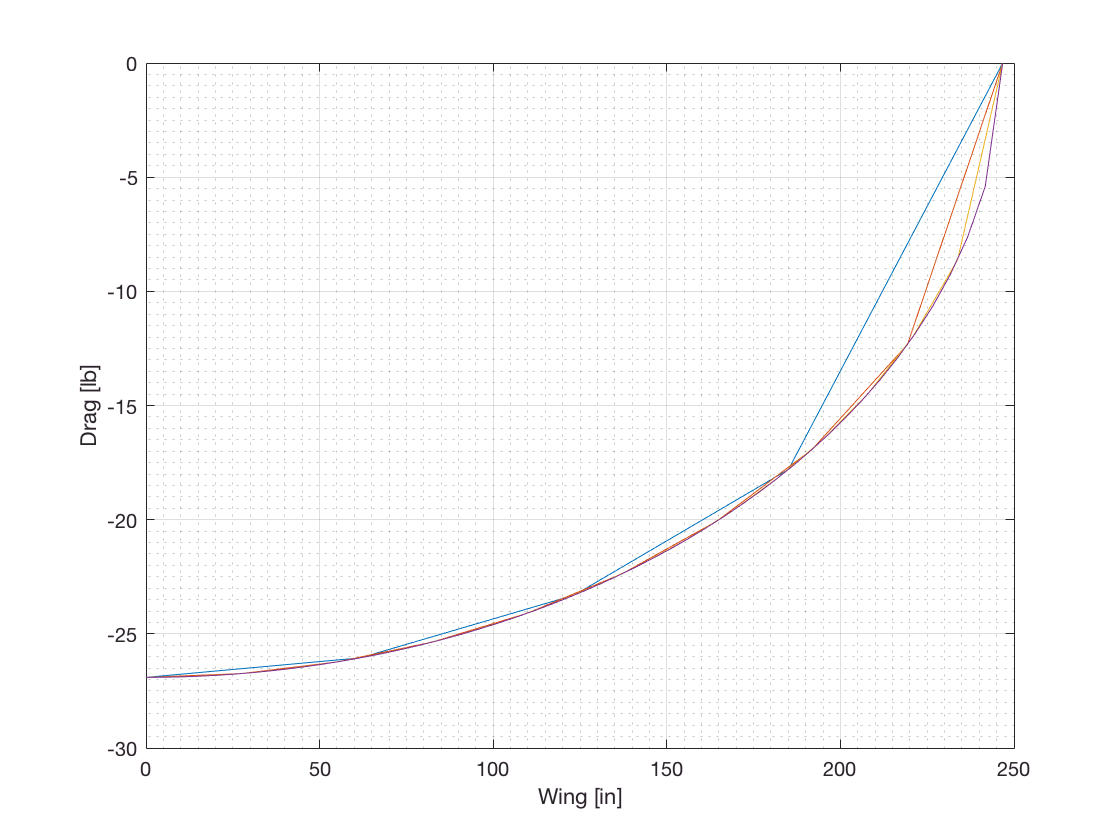

figure('Name','Discrete Lift/Drag Diagram')
plot(x5,Dx5,x10,Dx10,x20,Dx20,x50,Dx50)
xlabel('Wing [in]')
ylabel('Drag [lb]')
grid on 
grid minor

A similar procedure to the one followed in the analytical development will be followed from here on. A major difference will be the numerical approximation of the computations.

ac = chord/4; % aerodynamic center

The lift force will be relocated to the aerodynamic center which results in both a distributed lift force and a distributed moment (in order to compensate the force's displacement).

The first step is to locate the reference coordinate system and compute a linear transformation of this system. In order to facilitate the analysis, the reference system will be located at the leading edge of the airfoil. The convenient placement of the coordinate system at this location will allow for non-negative quantities being transformed to the aerodynamic center-based reference system.

acAxis = ac-(0.125.*chord); % shift the reference y-axis

The distributed lift load is originally located at the center of the horizontal section of the linearized NACA 0012 being analyzed. The following section will calculate the initial and aerodynamic center-based load location.

L_originalLocation = (0.125*chord)+(0.5*0.45*chord);
L_acLocation       = L_originalLocation-ac;

In order to translate the lift force to the aerodynamic center-based, a distributed moment must be added in order to account for the resulting effect.


$$M(x) = L(x)*d$$


Mx5  = Lx5*L_acLocation;
Mx10 = Lx10*L_acLocation;
Mx20 = Lx20*L_acLocation;
Mx50 = Lx50*L_acLocation;

The following code block is only executable in Matlab releases greater than or equal to R2016a. This is due to the [`yyaxis`](https://www.mathworks.com/help/matlab/ref/yyaxis.html) function call which was introduced in the 2016a Matlab release as a core addition to the graphics engine.

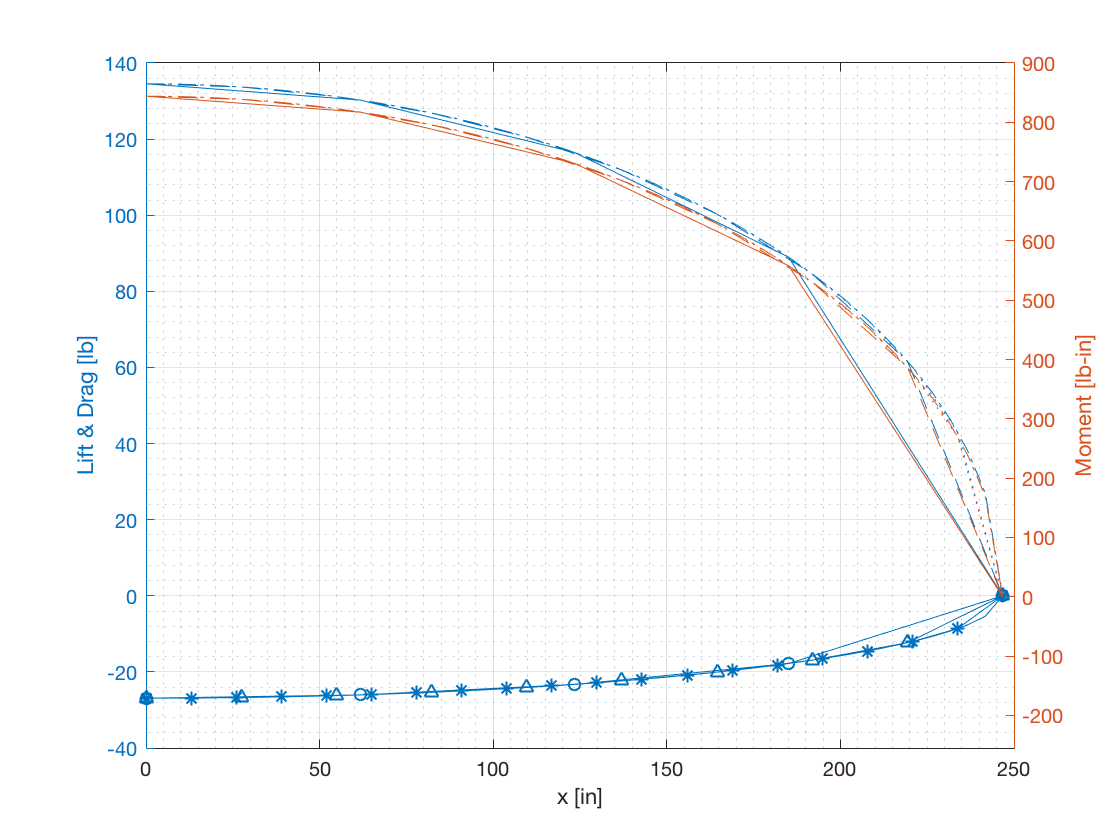

MatlabRelease = {'2016a','2016b','2017a','2017b','2018a','2018b','2019a','2019b'};
if sum(strcmp(version('-Release'), MatlabRelease)) > 0
    figure('Name','Lift, Drag and Moment')
    yyaxis left
    plot(x5,Lx5,x10,Lx10,x20,Lx20,x50,Lx50,x5,Dx5,x10,Dx10,x20,Dx20,x50,Dx50)
    ylabel('Lift & Drag [lb]')
    yyaxis right
    plot(x5,Mx5,x10,Mx10,x20,Mx20,x50,Mx50)
    ylabel('Moment [lb-in]')
    xlabel('x [in]')
    axis([0 250 -255 900])
    grid on 
    grid minor
end

Now, the pair of concentrated loads for the engines must be mathematically translated to the aerodynamic center in order to procede with the analysis. Recall the location where the engines are located as:


$$P1(x = \frac{2b}{5}, y =0, z=\frac{c}{3})\\
P2(x = \frac{-2b}{5}, y =0, z=\frac{c}{3})\\$$


This pair of concentrated loads act downwardly along the z-axis. Note that they are located originally at $\frac{1}{3}$ the length of the chord and must be translated to $\frac{1}{4}$ the length of the chord in order to analyze the system with respect to the aerodynamic center. The distance from the original location to the aerodynamic center is calculated as:


$$\frac{\Delta d}{c} = \frac{1}{3}-\frac{1}{4} =\frac{4}{12}-\frac{3}{12} =\frac{1}{12}\\

\Delta d = \frac{c}{12} \approx 5.2280~[in]$$


Engine_ac = chord/12;

Therefore, the engine loads and moments can be expressed as:

P1  = -14330;       % lb
P2  = -14330;       % lb
MP1 = P1*Engine_ac; % lb-in
MP2 = P2*Engine_ac; % lb-in

Given this set of equations, the shear and moment diagrams for half the wingspan can be computed and can be generalized through symetry to the opposite half.

The following code segments will compute the reactions at the wing root for the given discretized loads.

Reactions associated with the x-axis:

% 5-Discrete Steps
NxxR5  = 0;
MxxR5  = trapz(x5,Mx5)-MP1;

% 10-Discrete Steps
NxxR10 = 0;
MxxR10 = trapz(x10,Mx10)-MP1;

% 20-Discrete Steps
NxxR20 = 0;
MxxR20 = trapz(x20,Mx20)-MP1;

% 50-Discrete Steps
NxxR50 = 0;
MxxR50 = trapz(x50,Mx50)-MP1;

The following cells performs a variable limit integration and evaluates the resulting anonymous function in the discrete intervals.

Lx_intX   = matlabFunction(int(Lx,x,[0,x])); 
Dx_intX   = matlabFunction(int(Dx,x,[0,x]));

Lx5_intX  = Lx_intX(x5);  Dx5_intX  = Dx_intX(x5);
Lx10_intX = Lx_intX(x10); Dx10_intX = Dx_intX(x10);
Lx20_intX = Lx_intX(x20); Dx20_intX = Dx_intX(x20);
Lx50_intX = Lx_intX(x50); Dx50_intX = Dx_intX(x50);

Reactions associated with the y-axis:

% 5-Discrete Steps
VyR5   = trapz(x5,Lx5)+P1;
MyyR5  = -trapz(x5,Dx5_intX);

% 10-Discrete Steps
VyR10  = trapz(x10,Lx10)+P1;
MyyR10 = -trapz(x10,Dx10_intX);

% 20-Discrete Steps
VyR20  = trapz(x20,Lx20)+P1;
MyyR20 = -trapz(x20,Dx20_intX);

% 50-Discrete Steps
VyR50  = trapz(x50,Lx50)+P1;
MyyR50 = -trapz(x50,Dx50_intX);

Reactions associated with the z-axis:

% 5-Discrete Steps
VzR5   = trapz(x5,Dx5);
MzzR5  = trapz(x5,Lx5_intX)+P1*(2*b)/5;

% 10-Discrete Steps
VzR10  = trapz(x10,Dx10);
MzzR10 = trapz(x10,Lx10_intX)+P1*(2*b)/5;

% 20-Discrete Steps
VzR20  = trapz(x20,Dx20);
MzzR20 = trapz(x20,Lx20_intX)+P1*(2*b)/5;

% 50-Discrete Steps
VzR50  = trapz(x50,Dx50);
MzzR50 = trapz(x50,Lx50_intX)+P1*(2*b)/5;

Print results for small sample comparison between analytical and numerical results. The largest error in trial runs was 4.6308%. This error is associated with the largest step size in the 5-step case. The `print` variable can be set to 1 in order to display numerical and analytical results.

print = 0;
if print == 1
    fprintf('x-axis \n')
    fprintf('%15.4f [lb-in] \n', [MxxR, MxxR5, MxxR10, MxxR20, MxxR50])
    fprintf('Max Error: %6.4f %% \n',double(100*abs(MxxR - MxxR5)/MxxR))
    fprintf('Min Error: %6.4f %% \n',double(100*abs(MxxR - MxxR50)/MxxR))
    
    fprintf('\nz-axis\n')
    fprintf('%15.4f [lb-in] \n', [MzzR, MzzR5, MzzR10, MzzR20, MzzR50])
    fprintf('Max Error: %6.4f %% \n',double(100*abs(MyyR - MyyR5)/MyyR))
    fprintf('Min Error: %6.4f %% \n',double(100*abs(MyyR - MyyR50)/MyyR))
    
    fprintf('\ny-axis\n')
    fprintf('%15.4f [lb-in] \n', [MyyR, MyyR5, MyyR10, MyyR20, MyyR50])
    fprintf('Max Error: %6.4f %% \n',double(100*abs(MzzR - MzzR5)/MzzR))
    fprintf('Min Error: %6.4f %% \n',double(100*abs(MzzR - MzzR50)/MzzR))
end

## Shear and moment equations

Array Initialization - The following code cell pre-allocates the discrete arrays that will be populated later in the code.

% x-axis
Nxx5  = zeros(1,5);
Nxx10 = zeros(1,10);
Nxx20 = zeros(1,20);
Nxx50 = zeros(1,50);
Mxx5  = zeros(1,5);  Mxx5(1) = MxxR5;
Mxx10 = zeros(1,10); Mxx10(1) = MxxR10;
Mxx20 = zeros(1,20); Mxx20(1) = MxxR20;
Mxx50 = zeros(1,50); Mxx50(1) = MxxR50;
% y-axis
Vy5   = zeros(1,5);  Vy5(1)  = VyR5;
Vy10  = zeros(1,10); Vy10(1) = VyR10;
Vy20  = zeros(1,20); Vy20(1) = VyR20;
Vy50  = zeros(1,50); Vy50(1) = VyR50;
Myy5  = zeros(1,5);  Myy5(1)  = MyyR5;
Myy10 = zeros(1,10); Myy10(1)  = MyyR10;
Myy20 = zeros(1,20); Myy20(1)  = MyyR20;
Myy50 = zeros(1,50); Myy50(1)  = MyyR50;
% z-axis
Vz5   = zeros(1,5);  Vz5(1)  = VzR5;
Vz10  = zeros(1,10); Vz10(1) = VzR10;
Vz20  = zeros(1,20); Vz20(1) = VzR20;
Vz50  = zeros(1,50); Vz50(1) = VzR50;
Mzz5  = zeros(1,5);  Mzz5(1)  = MzzR5;
Mzz10 = zeros(1,10); Mzz10(1)  = MzzR10;
Mzz20 = zeros(1,20); Mzz20(1)  = MzzR20;
Mzz50 = zeros(1,50); Mzz50(1)  = MzzR50;

The following segment makes extensive use of flow control in order to stop value allocation on a per case base and switching equations based on conditional structures. This design allos for the complete and efficient allocation of several loops into a single `for` loop. The numerical integral is evaluated using a trapezoid method whose ending boundary is defined by the current state of the loop. This facilitates the efficient evaluation of a numerical integral with a growing upper-boundary.

for ii = 2:length(x50)
   % This initial contitional statement stops the allocation
   % of values to the array based on the number of discrete
   % steps associated with the particular case. This also 
   % allows for the combination of separate |for| loops into
   % a single loop whose length is bounded by the largest 
   % step size.
   if ii <= 5
       if x5(ii)<(2*WingLength/5)
           Mxx5(ii)  = MxxR5 - (trapz(x5(1:ii),Mx5(1:ii)));
           Vy5(ii)   = VyR5 - (trapz(x5(1:ii),Lx5(1:ii))); 
           Myy5(ii)  = MyyR5 - (-trapz(x5(1:ii),Dx5_intX(1:ii)));
           Vz5(ii)   = VzR5 - trapz(x5(1:ii),Dx5(1:ii)); 
           Mzz5(ii)  = MzzR5 - trapz(x5(1:ii),Lx5_intX(1:ii));
       % Discontinuity Introduction - This conditional statement
       % switches equations at the engine's location.
       elseif x5(ii)>(2*WingLength/5)
           Mxx5(ii)  = MxxR5 - (trapz(x5(1:ii),Mx5(1:ii))-MP1);
           Vy5(ii)   = VyR5 - (trapz(x5(1:ii),Lx5(1:ii))+P1); 
           Myy5(ii)  = MyyR5 - (-trapz(x5(1:ii),Dx5_intX(1:ii)));
           Vz5(ii)   = VzR5 - trapz(x5(1:ii),Dx5(1:ii)); 
           Mzz5(ii)  = MzzR5 - (trapz(x5(1:ii),Lx5_intX(1:ii))+P1*(2*b)/5);
       end
   end
   if ii <= 10
       if x10(ii)<(2*WingLength/5)
           Mxx10(ii) = MxxR10 - (trapz(x10(1:ii),Mx10(1:ii)));
           Vy10(ii)  = VyR10 - (trapz(x10(1:ii),Lx10(1:ii))); 
           Myy10(ii) = MyyR10 - (-trapz(x10(1:ii),Dx10_intX(1:ii)));
           Vz10(ii)  = VzR10 - trapz(x10(1:ii),Dx10(1:ii)); 
           Mzz10(ii) = MzzR10 - trapz(x10(1:ii),Lx10_intX(1:ii));
       % Discontinuity Introduction - This conditional statement
       % switches equations at the engine's location.
       elseif x10(ii)>(2*WingLength/5)
           Mxx10(ii) = MxxR10 - (trapz(x10(1:ii),Mx10(1:ii))-MP1);
           Vy10(ii)  = VyR10 - (trapz(x10(1:ii),Lx10(1:ii))+P1); 
           Myy10(ii) = MyyR10 - (-trapz(x10(1:ii),Dx10_intX(1:ii)));
           Vz10(ii)  = VzR10 - trapz(x10(1:ii),Dx10(1:ii)); 
           Mzz10(ii) = MzzR10 - (trapz(x10(1:ii),Lx10_intX(1:ii))+P1*(2*b)/5);
       end
   end
   if ii <= 20
       if x20(ii)<(2*WingLength/5)
           Mxx20(ii) = MxxR20 - (trapz(x20(1:ii),Mx20(1:ii)));
           Vy20(ii)  = VyR20 - (trapz(x20(1:ii),Lx20(1:ii))); 
           Myy20(ii) = MyyR20 - (-trapz(x20(1:ii),Dx20_intX(1:ii)));
           Vz20(ii)  = VzR20 - trapz(x20(1:ii),Dx20(1:ii)); 
           Mzz20(ii) = MzzR20 - trapz(x20(1:ii),Lx20_intX(1:ii));
       % Discontinuity Introduction - This conditional statement
       % switches equations at the engine's location.
       elseif x20(ii)>(2*WingLength/5)
           Mxx20(ii) = MxxR20 - (trapz(x20(1:ii),Mx20(1:ii))-MP1);
           Vy20(ii)  = VyR20 - (trapz(x20(1:ii),Lx20(1:ii))+P1); 
           Myy20(ii) = MyyR20 - (-trapz(x20(1:ii),Dx20_intX(1:ii)));
           Vz20(ii)  = VzR20 - trapz(x20(1:ii),Dx20(1:ii)); 
           Mzz20(ii) = MzzR20 - (trapz(x20(1:ii),Lx20_intX(1:ii))+P1*(2*b)/5);
       end
   end
   if ii <= 50
       if x50(ii)<(2*WingLength/5)
           Mxx50(ii) = MxxR50 - (trapz(x50(1:ii),Mx50(1:ii)));
           Vy50(ii)  = VyR50 - (trapz(x50(1:ii),Lx50(1:ii))); 
           Myy50(ii) = MyyR50 - (-trapz(x50(1:ii),Dx50_intX(1:ii)));
           Vz50(ii)  = VzR50 - trapz(x50(1:ii),Dx50(1:ii)); 
           Mzz50(ii) = MzzR50 - trapz(x50(1:ii),Lx50_intX(1:ii));
       % Discontinuity Introduction - This conditional statement
       % switches equations at the engine's location.
       elseif x50(ii)>(2*WingLength/5)
           Mxx50(ii) = MxxR50 - (trapz(x50(1:ii),Mx50(1:ii))-MP1);
           Vy50(ii)  = VyR50 - (trapz(x50(1:ii),Lx50(1:ii))+P1); 
           Myy50(ii) = MyyR50 - (-trapz(x50(1:ii),Dx50_intX(1:ii)));
           Vz50(ii)  = VzR50 - trapz(x50(1:ii),Dx50(1:ii)); 
           Mzz50(ii) = MzzR50 - (trapz(x50(1:ii),Lx50_intX(1:ii))+P1*(2*b)/5);
       end
   end
end

# Problem 4

## Numerical Shear and Moment Diagram - x axis

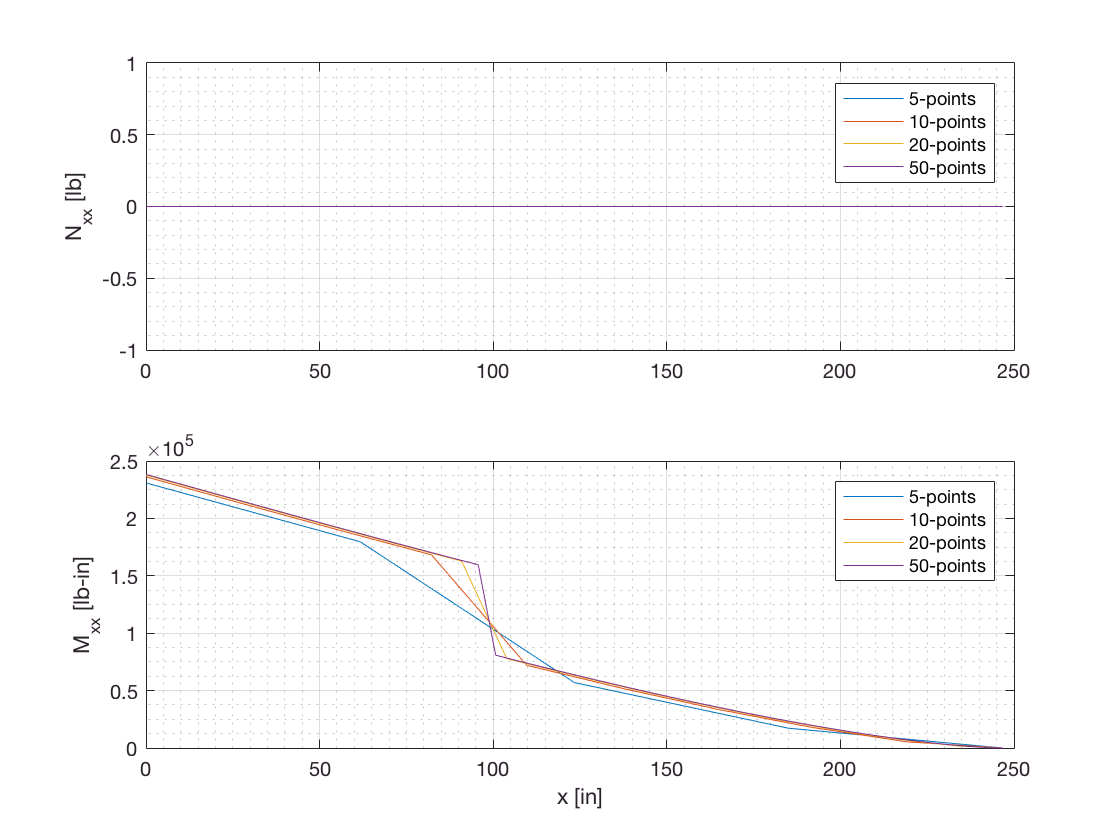

figure('Name','Numerical Shear and Moment Diagram - x axis')
subplot(2,1,1)
plot(x5,Nxx5,x10,Nxx10,x20,Nxx20,x50,Nxx50)
ylabel('N_{xx} [lb]')
grid on
grid minor
legend('5-points','10-points','20-points','50-points')
subplot(2,1,2)
plot(x5,Mxx5,x10,Mxx10,x20,Mxx20,x50,Mxx50)
xlabel('x [in]')
ylabel('M_{xx} [lb-in]')
legend('5-points','10-points','20-points','50-points')
grid on
grid minor

## Numerical Shear and Moment Diagram - y axis

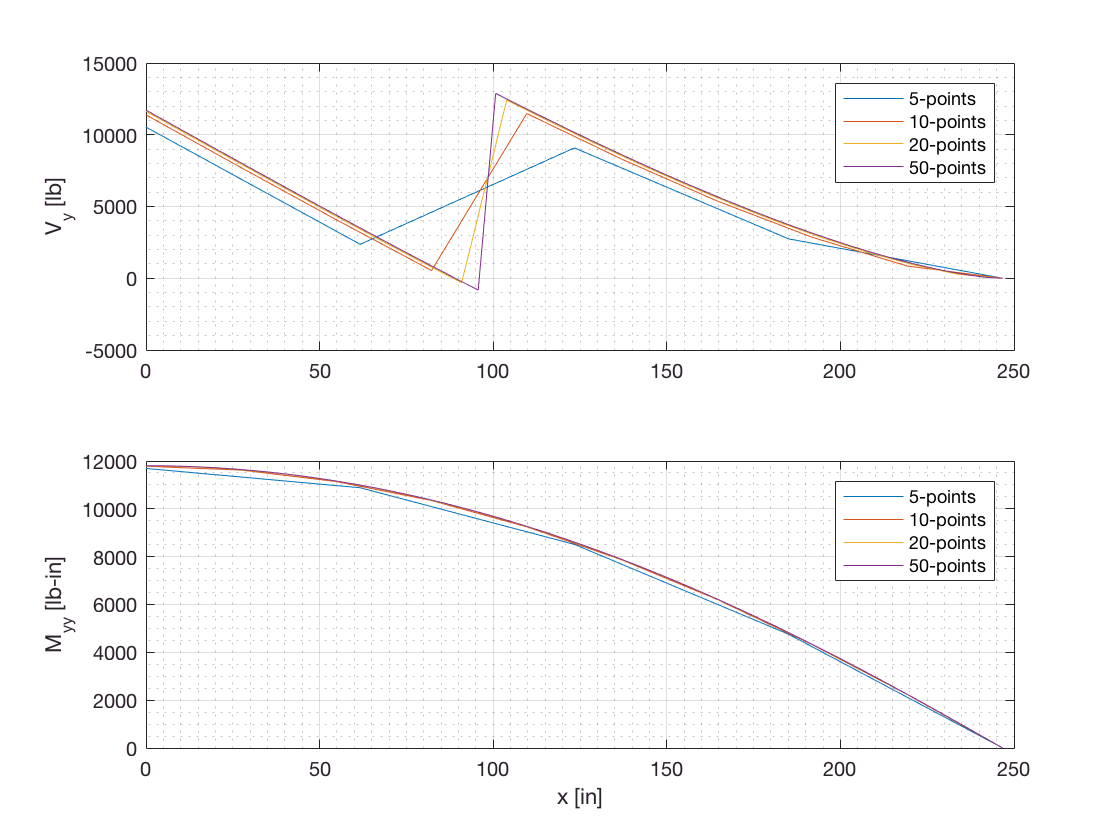

figure('Name','Numerical Shear and Moment Diagram - y axis')
subplot(2,1,1)
plot(x5,Vy5,x10,Vy10,x20,Vy20,x50,Vy50)
ylabel('V_{y} [lb]')
grid on
grid minor
legend('5-points','10-points','20-points','50-points')
subplot(2,1,2)
plot(x5,Myy5,x10,Myy10,x20,Myy20,x50,Myy50)
xlabel('x [in]')
ylabel('M_{yy} [lb-in]')
legend('5-points','10-points','20-points','50-points')
grid on
grid minor

## Numerical Shear and Moment Diagram - z axis

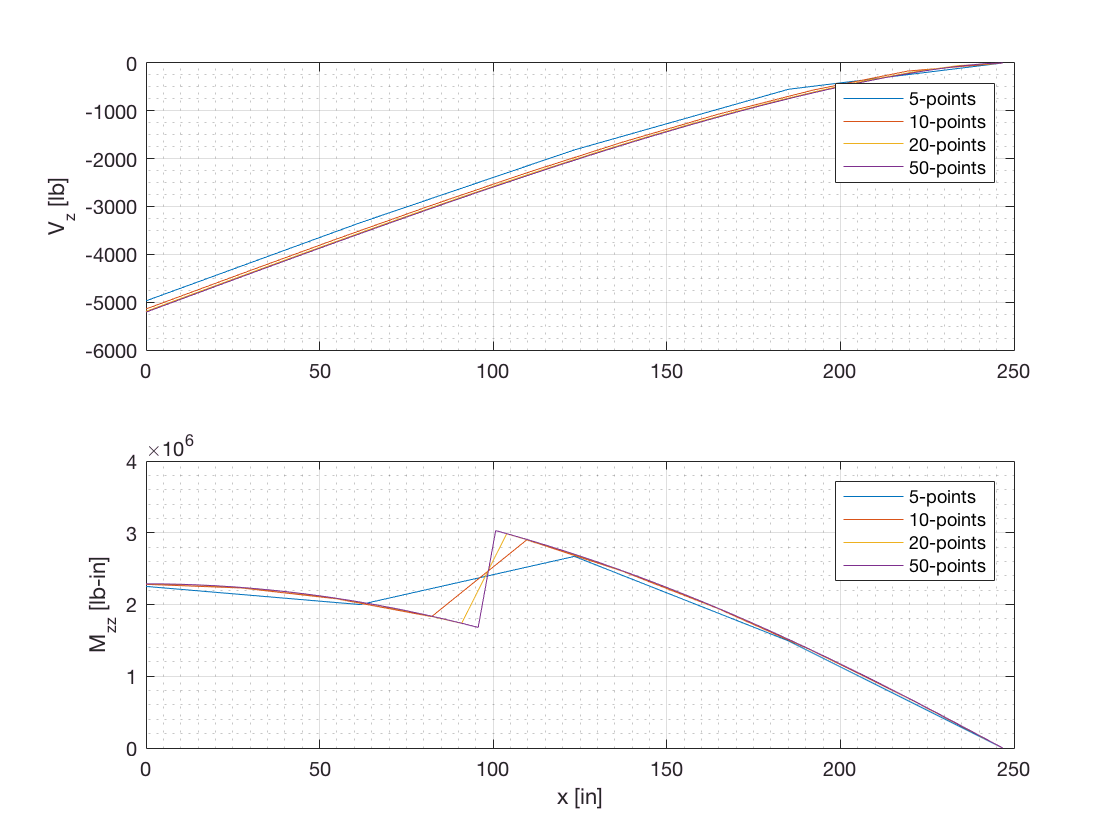

figure('Name','Numerical Shear and Moment Diagram - z axis')
subplot(2,1,1)
plot(x5,Vz5,x10,Vz10,x20,Vz20,x50,Vz50)
ylabel('V_{z} [lb]')
grid on
grid minor
legend('5-points','10-points','20-points','50-points')
subplot(2,1,2)
plot(x5,Mzz5,x10,Mzz10,x20,Mzz20,x50,Mzz50)
xlabel('x [in]')
ylabel('M_{zz} [lb-in]')
legend('5-points','10-points','20-points','50-points')
grid on
grid minor

# Final Test

## Euler-Bernoulli - Analytical Approach

## First and Second Moment of Area and Centroid

The following code cell is taken from a previous homework and is *chunked* into a single cell for eased execution. The airfoil plots have been suppressed, but can be enabled by setting `graphOut` to 1.

Beta = atand(0.1/0.45);
filename = 'user-000.csv';
delimiter = ',';
startRow = 10;
endRow = 210;
formatSpec = '%f%f%[^\n\r]';
fileID = fopen(filename,'r');
dataArray = textscan(fileID, formatSpec, endRow-startRow+1, 'Delimiter',... 
    delimiter, 'HeaderLines', startRow-1, 'ReturnOnError', false);
fclose(fileID);
xNACA0012 = dataArray{:, 1}/1.5939922481;
yNACA0012 = dataArray{:, 2}/1.3429;
clearvars filename delimiter startRow endRow formatSpec fileID dataArray ans;
filename = 'user-000.csv';
delimiter = ',';
startRow = 214;
endRow = 314;
formatSpec = '%f%f%[^\n\r]';
fileID = fopen(filename,'r');
dataArray = textscan(fileID, formatSpec, endRow-startRow+1, 'Delimiter',...
    delimiter, 'HeaderLines', startRow-1, 'ReturnOnError', false);
fclose(fileID);
xNACA0012_Camber = dataArray{:, 1}/1.5939922481;
yNACA0012_Camber = dataArray{:, 2};
clearvars filename delimiter startRow endRow formatSpec ...
    fileID dataArray ans;
filename = 'user-000.csv';
delimiter = ',';
startRow = 318;
formatSpec = '%f%f%[^\n\r]';
fileID = fopen(filename,'r');
dataArray = textscan(fileID, formatSpec, 'Delimiter', delimiter, ...
    'HeaderLines' ,startRow-1, 'ReturnOnError', false);
fclose(fileID);
xNACA0012_Chord = dataArray{:, 1}/1.5939922481;
yNACA0012_Chord = dataArray{:, 2};
clearvars filename delimiter startRow formatSpec fileID dataArray ans;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
graphOut =0;%% If 1, plot; else, hide plots %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

if graphOut == 1;
    figure('Name','NACA0012')
    plot(xNACA0012,yNACA0012,xNACA0012_Camber,yNACA0012_Camber,...
        xNACA0012_Chord,yNACA0012_Chord)
    grid on
    grid minor
    axis([-1 101/1.5939922481 -25 25])
end

chord = max(xNACA0012_Chord);
initLinear = (1.249440000000000e+01)/1.5939922481; 
endLinear  = (5.313950000000000e+01)/1.5939922481; 

for ii = 1:numel(xNACA0012)
    if xNACA0012(ii) > initLinear & xNACA0012(ii) < endLinear
        if yNACA0012(ii) < 0
            replacement = yNACA0012(find(xNACA0012 == initLinear));
            yNACA0012(ii) = replacement(2);
        elseif yNACA0012(ii) > 0
            replacement = yNACA0012(find(xNACA0012 == initLinear));
            yNACA0012(ii) = replacement(1);
        end
    end
end

if graphOut == 1
    figure('Name','NACA0012 - Simplified')
    plot(xNACA0012,yNACA0012,xNACA0012_Camber,yNACA0012_Camber,...
        xNACA0012_Chord,yNACA0012_Chord)
    grid on
    grid minor
    axis([-1 101/1.5939922481 -25 25])
end

h = sum(abs(replacement));
b1 = 0.45*max(xNACA0012_Chord);
b2 = b1;
b4 = max(xNACA0012_Chord)*.25/cosd(Beta);
b5 = b4;
b6 = abs(h - 2*sind(Beta)*b4);

t  = h/4;
t1 = 0.4*t;
t2 = t1;
t3 = t2;
t4 = t3;
t5 = t4;
t6 = 0.6*t;
t7 = t6;

cX = xNACA0012(find(xNACA0012<=(chord*.125)));
cY = yNACA0012(find(xNACA0012<=(chord*.125)));
b3 = 0;

for ii = 2:numel(cX)
    b3 = b3 + sqrt(((cX(ii)-cX(ii-1))^2)+((cY(ii)-cY(ii-1))^2));
end

[Izz4,Iyy4,z4,y4,A4] = TrapezoidInertia_Bottom(Beta,t1,t6,chord,h);
[Izz5,Iyy5,z5,y5,A5] = TrapezoidInertia_Top(Beta,t5,t7,chord,h);

A1 = b1*t1;
A2 = b2*t2;
A3 = b3*t3;
A6 = b6*t6;

Section = [1:6]';
Modulus = [60,60,80,40,40,50]'.*10^6; % psi
Eo = min(Modulus);
ModRatio = Modulus./Eo;
ActualArea = [A1,A2,A3,A4,A5,A6]';
TotalActualArea = sum(ActualArea);
WeightArea = ModRatio.*ActualArea;
TotalWeightArea = sum(WeightArea);

disp(array2table([Section,Modulus,ModRatio,ActualArea,WeightArea],...
    'VariableName',{'Section','Modulus_psi',...
    'Modulus_ratio','ActualArea','WeightedArea'}))

          Section               Modulus_psi            Modulus_ratio             ActualArea             WeightedArea    
    ____________________    ____________________    ____________________    ____________________    ____________________

    1.00000000000000e+00    6.00000000000000e+07    1.50000000000000e+00    2.12524016770317e+01    3.18786025155475e+01
    2.00000000000000e+00    6.00000000000000e+07    1.50000000000000e+00    2.12524016770317e+01    3.18786025155475e+01
    3.00000000000000e+00    8.00000000000000e+07    2.00000000000000e+00    1.38159265309623e+01    2.76318530619247e+01
    4.00000000000000e+00    4.00000000000000e+07    1.00000000000000e+00    3.51059495675126e+00    3.51059495675126e+00
    5.00000000000000e+00    4.00000000000000e+07    1.00000000000000e+00    3.51059495675126e+00    3.5


%%%% y - Centroid
y1 = (h/2) - (t1/2);
y2 = (-h/2) + (t4/2);
y3 = 0;
y6 = 0;
yCentroid = [y1,y2,y3,y4,y5,y6]';

%%%% z - Centroid
z1 = -b1/2;
z2 = -b2/2;
z3 = (1/A3)*(.5*abs(trapz((cX.^2 - (cX-t3).^2)))); % Approximate the 4th 
                                                   % degree leading edge
                                                   % as a parabola with  
                                                   % thickness.
z6 = -((.70-.125)*chord)+t6;
zCentroid = [z1,z2,z3,z4,z5,z6]';

%%%% First Moment of Area - z
Qz1 = y1*A1;
Qz2 = y2*A2;
Qz3 = y3*A3;
Qz4 = y4*A4;
Qz5 = y5*A5;
Qz6 = y6*A6;
QzVec = [Qz1,Qz2,Qz3,Qz4,Qz5,Qz6]';
QzTotal = sum(QzVec);
QzWeighted = QzVec.*ModRatio;
QzTotalWeighted = sum(QzWeighted);
fprintf('Qz = %7.4f [in^3]\n',QzTotal)

Qz =  0.0000 [in^3]


fprintf('Qz_Weighted = %7.4f [in^3]\n',QzTotalWeighted)

Qz_Weighted =  0.0000 [in^3]



%%%% First Moment of Area - y
Qy1 = z1*A1;
Qy2 = z2*A2;
Qy3 = z3*A3;
Qy4 = z4*A4;
Qy5 = z5*A5;
Qy6 = z6*A6;
QyVec = [Qy1,Qy2,Qy3,Qy4,Qy5,Qy6]';
QyTotal = sum(QyVec);
QyWeighted = QyVec.*ModRatio;
QyTotalWeighted = sum(QyWeighted);
fprintf('Qy = %7.4f [in^3]\n',QyTotal)

Qy = -762.3027 [in^3]


fprintf('Qy_Weighted = %7.4f [in^3]\n',QyTotalWeighted)

Qy_Weighted = -988.6585 [in^3]


disp(array2table([Section,ModRatio,ActualArea,WeightArea,zCentroid,...
    yCentroid,QzVec,QyVec,QzWeighted,QyWeighted],...
    'VariableName',{'Section','Modulus_ratio','ActualArea',...
    'WeightedArea','Centroid_z','Centroid_y','Qz','Qy',...
    'Qz_Weighted','Qy_Weighted'}))

          Section              Modulus_ratio             ActualArea             WeightedArea             Centroid_z               Centroid_y                   Qz                       Qy                   Qz_Weighted              Qy_Weighted     
    ____________________    ____________________    ____________________    ____________________    _____________________    _____________________    _____________________    _____________________    _____________________    _____________________

    1.00000000000000e+00    1.50000000000000e+00    2.12524016770317e+01    3.18786025155475e+01    -1.41155015194205e+01     3.38761635266960e+00     7.199498345461

zCentroid = QyTotal/TotalActualArea;
yCentroid = QzTotal/TotalActualArea;
zCentroidWeight = QyTotalWeighted/TotalWeightArea;
yCentroidWeight = QzTotalWeighted/TotalWeightArea;
fprintf('z Centroid = %6.4f [in]\ny Centroid = %6.4f [in]\n',zCentroid,yCentroid)

z Centroid = -11.9163 [in]
y Centroid = 0.0000 [in]


fprintf('Modulus Weighted z Centroid = %6.4f [in] \nModulus Weighted y Centroid = %6.4f [in] \n',...
    zCentroidWeight,yCentroidWeight)

Modulus Weighted z Centroid = -9.9666 [in] 
Modulus Weighted y Centroid = 0.0000 [in] 



%%%%% z - Geometrical - About Reference Axis
Izz1 = (((b1)*(t1^3))/12)+((y1^2)*A1);
Izz2 = (((b2)*(t4^3))/12)+((y2^2)*A2);
Izz3 = (((4/15)*(h/2)^3)*(0.125*chord))+((y3^2)*A3);
Izz4 = Izz4+((y4^2)*A4);
Izz5 = Izz5+((y5^2)*A5);
Izz6 = (((t6)*(b6^3))/12)+((y6^2)*A6);
Izz  = [Izz1; Izz2; Izz3; Izz4; Izz5; Izz6];
IzzTotal = sum(Izz);

%%%%% y - Geometrical - About Reference Axis
Iyy1 = (((b1^3)*(t1))/12)+((z1^2)*A1);
Iyy2 = (((b2^3)*(t4))/12)+((z2^2)*A2);
Iyy3 = (((16/175)*(h/2))*(0.125*chord)^3)+((z3^2)*A3);
Iyy4 = Iyy4+((z4^2)*A4);
Iyy5 = Iyy5+((z5^2)*A5);
Iyy6 = (((t6^3)*(b6))/12)+((z6^2)*A6);
Iyy  = [Iyy1; Iyy2; Iyy3; Iyy4; Iyy5; Iyy6];
IyyTotal = sum(Iyy);

%%%%% x - Weighted - About Reference Axis
Izz1_weighted = ModRatio(1)*(((b1)*(t1^3))/12)+((y1^2)*WeightArea(1));
Izz2_weighted = ModRatio(2)*(((b2)*(t4^3))/12)+((y2^2)*WeightArea(2));
Izz3_weighted = ModRatio(3)*(((4/15)*(h/2)^3)*(0.125*chord))+((y3^2)*WeightArea(3));
Izz4_weighted = ModRatio(4)*Izz4+((y4^2)*WeightArea(4));
Izz5_weighted = ModRatio(5)*Izz5+((y5^2)*WeightArea(5));
Izz6_weighted = ModRatio(6)*(((t6)*(b6^3))/12)+((y6^2)*WeightArea(6));
Izz_weighted  = [Izz1_weighted; Izz2_weighted; Izz3_weighted; Izz4_weighted; Izz5_weighted; Izz6_weighted];
IzzTotal_weighted = sum(Izz_weighted);

%%%%% y - Weighted - About Reference Axis
Iyy1_weighted = ModRatio(1)*(((b1^3)*(t1))/12)+((z1^2)*WeightArea(1));
Iyy2_weighted = ModRatio(2)*(((b2^3)*(t4))/12)+((z2^2)*WeightArea(2));
Iyy3_weighted = ModRatio(3)*(((16/175)*(h/2))*(0.125*chord)^3)+((z3^2)*WeightArea(3));
Iyy4_weighted = ModRatio(4)*Iyy4+((z4^2)*WeightArea(4));
Iyy5_weighted = ModRatio(5)*Iyy5+((z5^2)*WeightArea(5));
Iyy6_weighted = ModRatio(6)*(((t6^3)*(b6))/12)+((z6^2)*WeightArea(6));
Iyy_weighted  = [Iyy1_weighted; Iyy2_weighted; Iyy3_weighted; Iyy4_weighted; Iyy5_weighted; Iyy6_weighted];
IyyTotal_weighted = sum(Iyy_weighted);

%%%%% Inertia Tables
disp(array2table([Section,ModRatio,ActualArea,WeightArea,...
    Izz,Iyy,Izz_weighted,Iyy_weighted],...
    'VariableName',{'Section','Modulus_ratio','ActualArea',...
    'WeightedArea','Izz','Iyy',...
    'Izz_Weighted','Iyy_Weighted'}))

          Section              Modulus_ratio             ActualArea             WeightedArea                Izz                     Iyy                 Izz_Weighted            Iyy_Weighted    
    ____________________    ____________________    ____________________    ____________________    ____________________    ____________________    ____________________    ____________________

    1.00000000000000e+00    1.50000000000000e+00    2.12524016770317e+01    3.18786025155475e+01    2.44895051504904e+02    5.64598055958654e+03    3.67342577257357e+02    8.46897083937982e+03
    2.00000000000000e+00    1.50000000000000e+00    2.12524016770317e+01    3.18786025155475e+01    2.44895051504904e+02    5.64598055958654e+03    

fprintf('Total: \nIzz  = %10.4f [in^4]\nIyy  = %10.4f [in^4]\nIzz* = %10.4f [in^4]\nIyy* = %10.4f [in^4]\n',...
    IzzTotal,IyyTotal,IzzTotal_weighted,IyyTotal_weighted)

Total: 
Izz  =   688.1449 [in^4]
Iyy  = 19568.7179 [in^4]
Izz* =  1131.1731 [in^4]
Iyy* = 32885.8225 [in^4]


IzzTotalCentroid = IzzTotal - (yCentroid^2)*TotalActualArea;
IyyTotalCentroid = IyyTotal - (zCentroid^2)*TotalActualArea;
IzzTotal_weightedCentroid = IzzTotal_weighted - (yCentroidWeight^2)*TotalWeightArea;
IyyTotal_weightedCentroid = IyyTotal_weighted - (zCentroidWeight^2)*TotalWeightArea;
fprintf('Total: \nIzz  = %10.4f [in^4]\nIyy  = %10.4f [in^4]\nIzz* = %10.4f [in^4]\nIyy* = %10.4f [in^4]\n',...
    IzzTotalCentroid,IyyTotalCentroid,IzzTotal_weightedCentroid,IyyTotal_weightedCentroid)

Total: 
Izz  =   688.1449 [in^4]
Iyy  = 10484.8802 [in^4]
Izz* =  1131.1731 [in^4]
Iyy* = 23032.2472 [in^4]


## Thermal Expansion

The following thermal conditions are imposed:

alpha = [6.0; 6.0; 7.0; 5.0; 5.0; 4.5].*10^-6;

disp(array2table([Section,ModRatio,Modulus,WeightArea,QzWeighted,QyWeighted,Izz_weighted,Iyy_weighted,alpha],...
    'VariableName',{'Section','Modulus_ratio','Modulus','WeightedArea',...
    'Qz_Weighted','Qy_Weighted','Izz_Weighted','Iyy_Weighted','ThermalExpansion'}))

          Section              Modulus_ratio              Modulus               WeightedArea             Qz_Weighted              Qy_Weighted             Izz_Weighted            Iyy_Weighted          ThermalExpansion  
    ____________________    ____________________    ____________________    ____________________    _____________________    _____________________    ____________________    ____________________    ____________________

    1.00000000000000e+00    1.50000000000000e+00    6.00000000000000e+07    3.18786025155475e+01     1.07992475181923e+02    -4.49982462245213e+02    3.67342577257357e+02    8.46897083937982e+03    6.00000000000000e-06
    2.00000000000000e+00    1.500000

From our problem statement,


$$\Delta T = 0.05*(\frac{b}{3} - x)\\
~~~ = \frac{329}{80} - \frac{x}{20} $$


The following equation can be implemented simbolically as,

dT_Sym   = 0.05*((b/3) - x);

The same expression is discretized as,

dT_Num5  = 0.05.*((b/3) - x5);  % 5-steps
dT_Num10 = 0.05.*((b/3) - x10); % 10-steps
dT_Num20 = 0.05.*((b/3) - x20); % 20-steps
dT_Num50 = 0.05.*((b/3) - x50); % 50-steps

Now, the reaction forces due to thermal loadings are computed as,


$$N_{xx}^{t} = E_{0} \int\int{\xi \alpha \Delta T dA} = E_0 \sum_{i = 1}^{6} A_{i}^{*}\alpha_{i} \Delta T_{i}\\

M_{yy}^{t} = E_{0} \int\int{\xi \alpha \Delta T zdA} = E_0 \sum_{i = 1}^{6}Q_{yi}^{*} \alpha_{i}\Delta T_{i}\\

M_{zz}^{t} = E_{0} \int\int{\xi \alpha \Delta T ydA} = E_0 \sum_{i = 1}^{6}Q_{zi}^{*} \alpha_{i}\Delta T_{i}\\$$


The expressions are fused into efficient computations. A naïve approach would be to write 3 individual loops of equal length, but it incurs in unwanted overhead. The first code optimization in the pipeline is denoted as loop fusion which is done by compilers in compiled languages. The three loops can be fused into a single loop because they loop over different data and have equal length. Matlab has array programming capabilities and the code optimization pipeline can go further to using vector processors and SIMD.

NxxT = Eo*(sum((WeightArea.*alpha.*dT_Sym))); pretty(NxxT)

7460143500195489945078125   22675208207281124453125 x
------------------------- - -------------------------
   73786976294838206464        18446744073709551616



MyyT = Eo*(sum((QyWeighted.*alpha.*dT_Sym))); pretty(MyyT)

1589009793006715203125 x   522784221899209301828125
------------------------ - ------------------------
   144115188075855872         576460752303423488



MzzT = Eo*(sum((QzWeighted.*alpha.*dT_Sym))); pretty(MzzT)

0



The strains can be calculated as,


$$e_{xx}=\frac{1}{E_{0}} \{1~y~z\} \left(\begin{array}{ccc} \frac{1}{A^*} & 0 & 0\\ 0 & 0 & - \frac{1}{R_{yy}^*}\\ 0 & \frac{1}{R_{zz}^*} & 0 \end{array}\right)

\left(\begin{array}{c} N_{xx} + N_{xx}^t\\ M_{yy} + M_{yy}^t\\ M_{zz} - M_{zz}^t \end{array}\right)$$


where $K_1$ and $K_2$ is defined in the cell below:

Iyz    = 0;
DeltaI = det([0, IyyTotal_weighted;-IzzTotal_weighted, 0]);
Ryz    = DeltaI/Iyz;
Rzz    = DeltaI/IzzTotal_weighted;
Ryy    = DeltaI/IyyTotal_weighted;
K1     = [(1/TotalWeightArea), 0     ,      0;... 
          0                  , -1/Ryz, -1/Ryy;...
          0                  , 1/Rzz , 1/Ryz];
K2     = [NxxR + NxxT; MyyR + MyyT; MzzR - MzzT];
exx    = (1/Eo)*[1, y, z]*K1*K2;

The stress $S_{xx}$ can be computed as,


$$S_{xx} = E(e_{xx} -\alpha \Delta T)$$


where 


$$E = E(y,z) ~~~ \alpha = \alpha(y,z)$$


The stress is thus defined in the following cell:

a      = sym('a');
E      = sym('E');
Sxx    = E*(exx-(a*dT_Sym));

The axial displacement equation ($u$) is 


$$E_{0}A^{*}u' = P_{u}=N_{xx}+N_{xx}^t\\

E_{0}A^{*}u(x) = \int P_{u}~dx+C_{1}=\int_{0}^{x}{(N_{xx}+N_{xx}^t)dx+C_1}=K_{1}\\

K_{1}=\mathrm{C_1} - \frac{22675208207281124453125\, x\, \left(2\, x - 329\right)}{73786976294838206464}\\

u(x) = \frac{2097152\, \mathrm{C_1}}{8321251482652547} - \frac{22675208207281124453125\, x\, \left(2\, x - 329\right)}{292778008410392172102475055104}
$$


% Displacement u
C1     = sym('C1');
Pu     = NxxR + NxxT;
K1     = int(Pu,x)+C1;
ux     = K1/(Eo*TotalWeightArea);
x      = 0;
C1     = solve(subs(ux),C1)

$$C1 = 0$$

x      = sym('x');
K1     = int(Pu,x)+C1;
ux     = K1/(Eo*TotalWeightArea);

$C_{1}$ can be derived by imposing the Boundary Conditions for this particular case. From the physical representation of the problem, it can be established that the wing's root has zero displacement. By imposing this condition to the equation, 


$$u(0) = \frac{2097152\, \mathrm{C_1}}{8321251482652547} - \frac{22675208207281124453125\, (0)\, \left(2\, (0) - 329\right)}{292778008410392172102475055104} = 0 \\ 

C_{1} = 0$$


The transverse displacement ($v$) is


$$E_{0}R_{yy}^{*}v''=M_{yy}+M_{yy}^{t}\\

E_{0}R_{yy}^{*}v'=\int{(M_{yy}+M_{yy}^{t})dx+C_{2}\\

E_{0}R_{yy}^{*}v=\int\int{(M_{yy}+M_{yy}^{t})dx+C_{2}x+C_{3}}\\

v(x) = \frac{\int\int{(M_{yy}+M_{yy}^{t})dx+C_{2}x+C_{3}}}{E_{0}R_{yy}^{*}}
$$


C2     = sym('C2');
C3     = sym('C3');
K2     = int(int(Myy_Sym + MyyT)) + C2*x + C3;
vx     = K2/(Eo*Ryy);
x      = 0;
C3     = solve(subs(vx),C3)

$$C3 = \frac{458643578740602517577874700541917185634917}{12980742146337069071326240823050240}$$

C2     = solve(subs(diff(vx)),C2)

$$C2 = 0$$

x      = sym('x');
K2     = int(int(Myy_Sym + MyyT)) + C2*x + C3;
vx     = K2/(Eo*Ryy);

From the established boundary conditions,


$$~v(x) \vert_{x=0} = 0\\
v'(x) \vert_{x=0} = 0$$


The integration constants $C_2$ and $C_{3}$ are printed at the cell. Matlab solves the resulting equation for the constants symbolically and prevents unwantend roundoff errors. The Matlab Symbolic Math Toolbox contains more details on the precision issue and how the SMT can help avoid roundoff errors.

The lateral displacement ($w$) and slope equations ($w'$) are


$$E_{0}R_{zz}^{*}w''=-(M_{zz}+M_{zz}^{t}) \\

E_{0}R_{zz}^{*}w'=-\int(M_{zz}+M_{zz}^{t})dx +C_{4}\\

E_{0}R_{zz}^{*}w=-\int\int(M_{zz}+M_{zz}^{t})dx +C_{4}x+C_{5}\\

w(x) =\frac{-\int\int(M_{zz}+M_{zz}^{t})dx +C_{4}x+C_{5}}{E_{0}R_{zz}^{*}}$$


C4      = sym('C4');
C5      = sym('C5');
Mzz_Sym = (heaviside(x)-heaviside(x-(2*b/5)))*Mzz1_Sym + (heaviside(x-(2*b/5))-heaviside(x-b))*Mzz2_Sym;
K3      = -(Mzz_Sym - MzzT);
wx      = (int(int(K3))+C4*x+C5)/(Eo*Rzz);

Once again, the integration constants are determined by imposing the physical boundary conditions,


$$~w(x) \vert_{x=0} = 0\\
w'(x) \vert_{x=0} = 0$$


x       = 0;
C5      = solve(subs(wx),C5)

$$C5 = 0$$

C4      = solve(subs(diff(wx)),C4);
if isempty(C4) == 1
    C4 = sym(0)
else
    C4
end

$$C4 = 0$$

x       = sym('x');
Mzz_Sym = (heaviside(x)-heaviside(x-(2*b/5)))*Mzz1_Sym + (heaviside(x-(2*b/5))-heaviside(x-b))*Mzz2_Sym;
K3      = -(Mzz_Sym - MzzT);
wx      = (int(int(K3))+C4*x+C5)/(Eo*Rzz);

The displacements at the wing tip can be computed by evaluating the functions at $x = b$.

uxTip   = double(limit(ux, x, b))

uxTip =     -3.143662358159374e-03


upxTip  = double(limit(diff(ux), x, b))

upxTip =     -5.096109192558256e-05


vxTip   = double(limit(vx, x, b))

vxTip =      6.530619976037795e-03


vpxTip  = double(limit(diff(vx), x, b))

vpxTip =      2.514753752464570e-03


wxTip   = double(limit(wx, x, b))

wxTip =     -7.304091160409919e-02


wpxTip  = double(limit(diff(wx),x , b))

wpxTip =     -4.656122795044120e-04


## Displacement and Slope Plots 

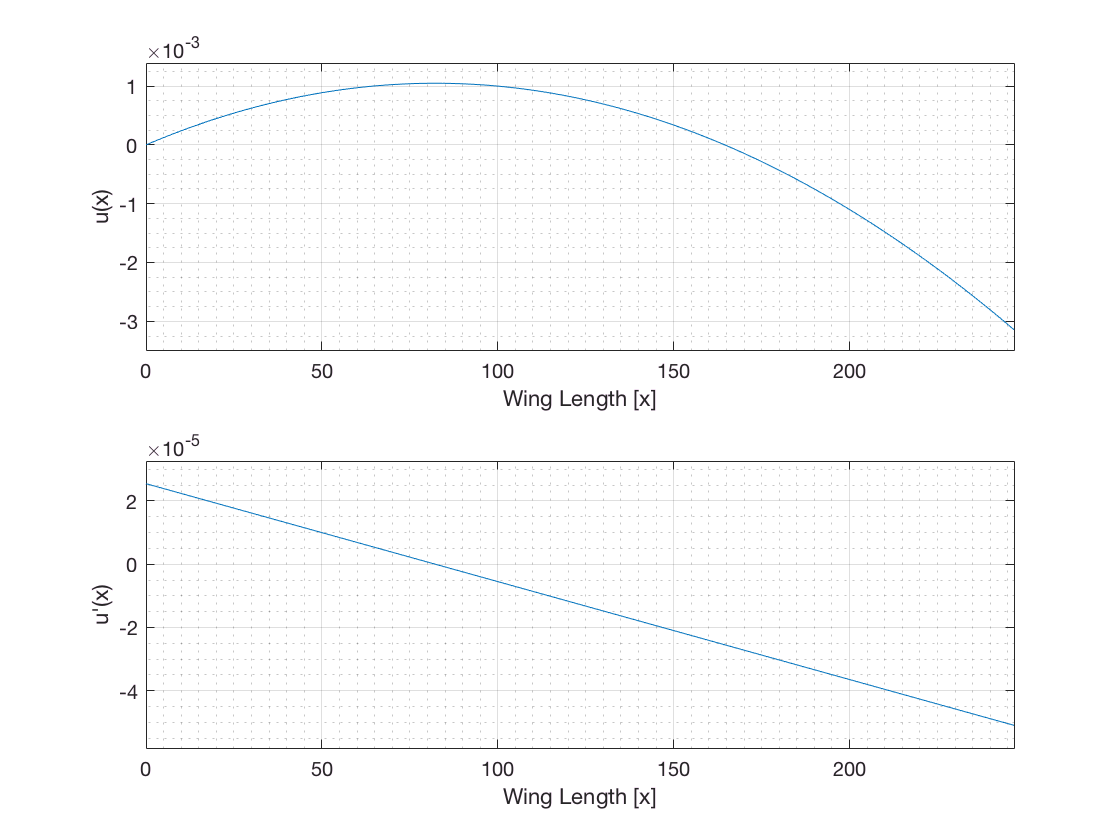

figure('Name','Ux')
subplot(2,1,1)
ezplot(ux,[0,b])
title('')
xlabel('Wing Length [x]')
ylabel('u(x)')
grid on
grid minor
subplot(2,1,2)
ezplot(diff(ux),[0,b])
title('')
xlabel('Wing Length [x]')
ylabel('u''(x)')
grid on
grid minor

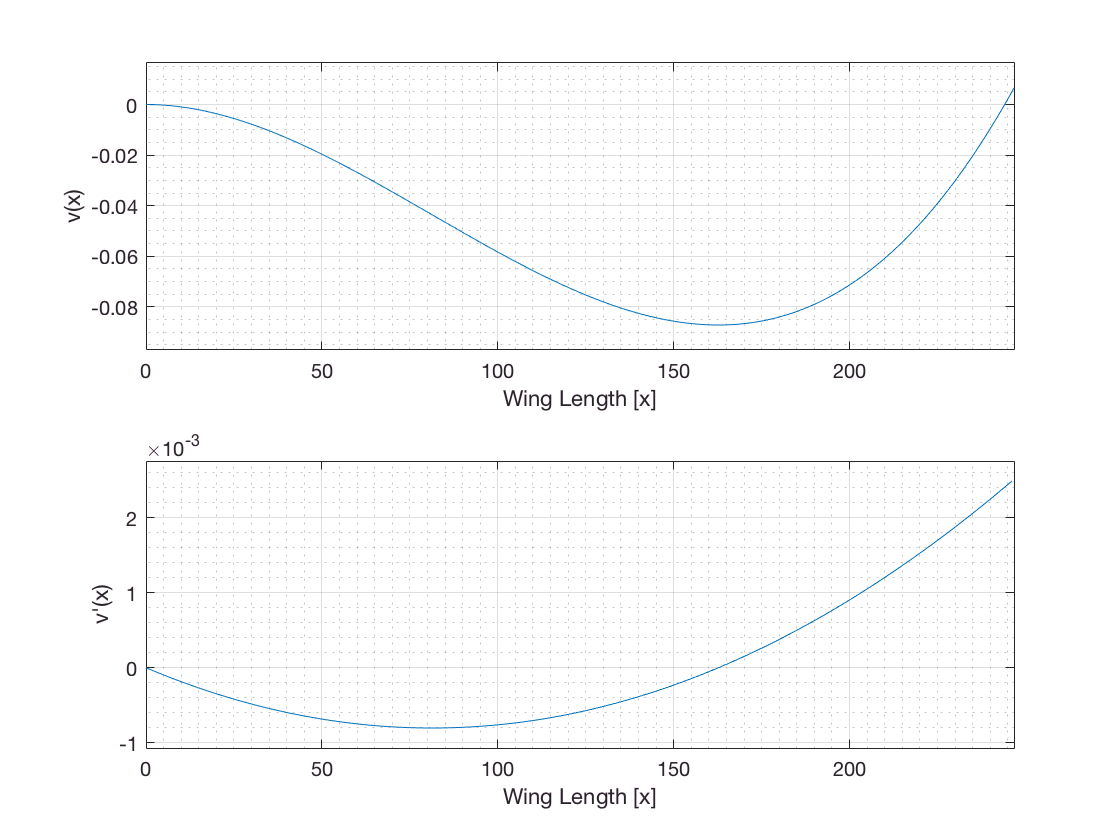

figure('Name','Vx')
subplot(2,1,1)
ezplot(vx,[0,b])
title('')
xlabel('Wing Length [x]')
ylabel('v(x)')
grid on
grid minor
subplot(2,1,2)
ezplot(diff(vx),[0,b])
title('')
xlabel('Wing Length [x]')
ylabel('v''(x)')
grid on
grid minor

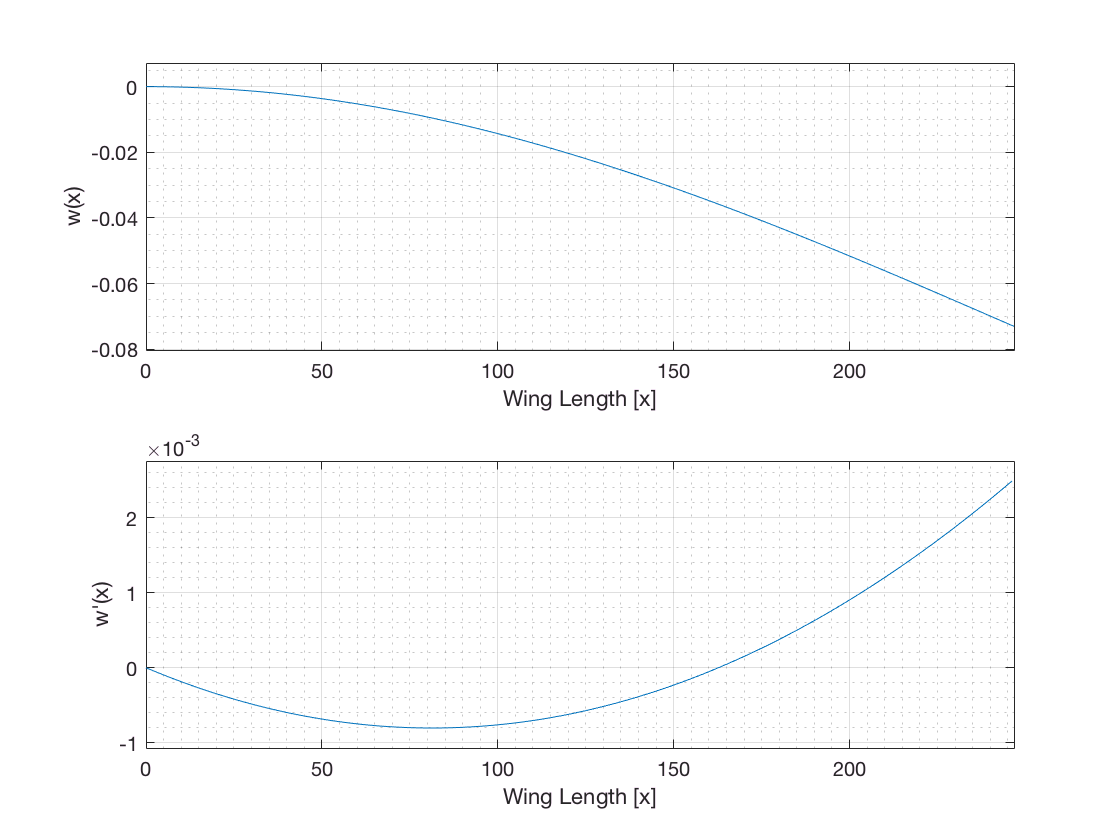

figure('Name','Wx')
subplot(2,1,1)
ezplot(wx,[0,b])
title('')
xlabel('Wing Length [x]')
ylabel('w(x)')
grid on
grid minor
subplot(2,1,2)
ezplot(diff(vx),[0,b])
title('')
xlabel('Wing Length [x]')
ylabel('w''(x)')
grid on
grid minor

## Euler-Bernoulli - Discrete Evaluation

upx     = matlabFunction(diff(ux));
ux      = matlabFunction(ux);
vpx     = matlabFunction(diff(vx));
vx      = matlabFunction(vx);
wpx     = matlabFunction(diff(wx));
wx      = matlabFunction(wx);

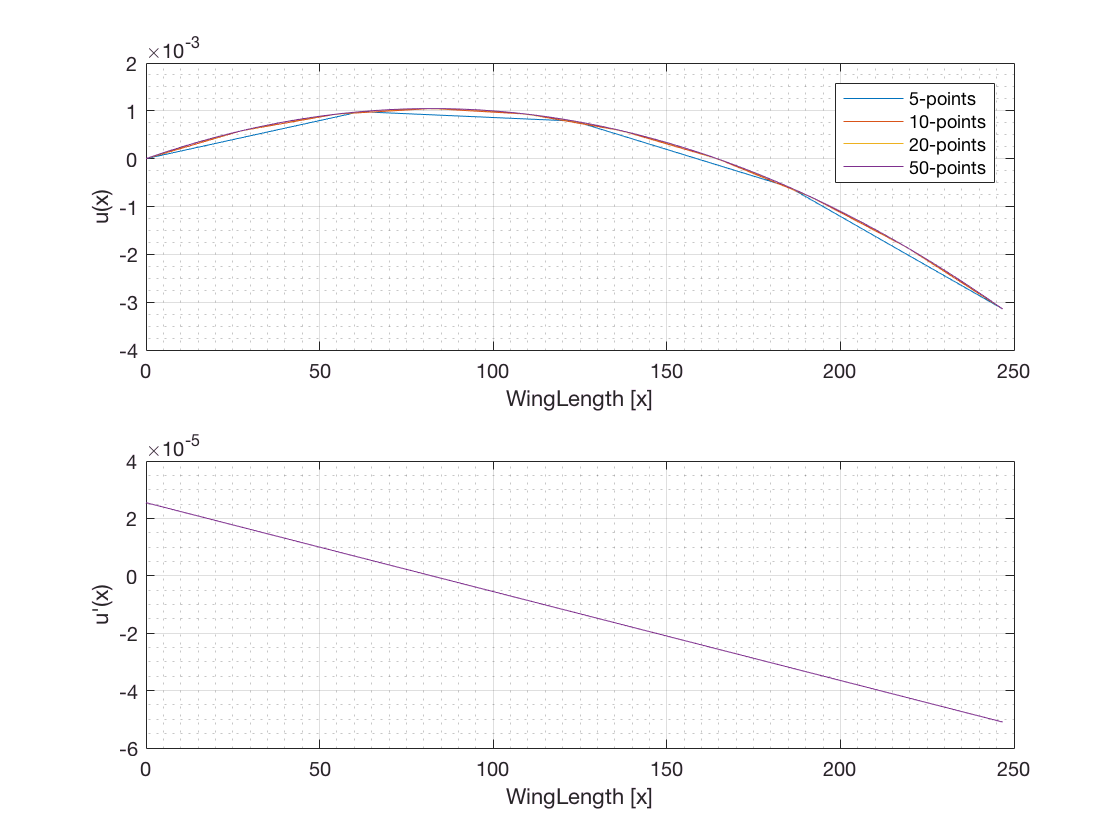

ux5     = ux(x5);
ux10    = ux(x10);
ux20    = ux(x20);
ux50    = ux(x50);
upx5    = upx(x5);
upx10   = upx(x10);
upx20   = upx(x20);
upx50   = upx(x50);
figure('Name','Uxp')
subplot(2,1,1)
plot(x5,ux5,x10,ux10,x20,ux20,x50,ux50)
xlabel('WingLength [x]')
ylabel('u(x)')
grid on 
grid minor
legend('5-points','10-points','20-points','50-points')
subplot(2,1,2)
plot(x5,upx5,x10,upx10,x20,upx20,x50,upx50)
xlabel('WingLength [x]')
ylabel('u''(x)')
grid on 
grid minor

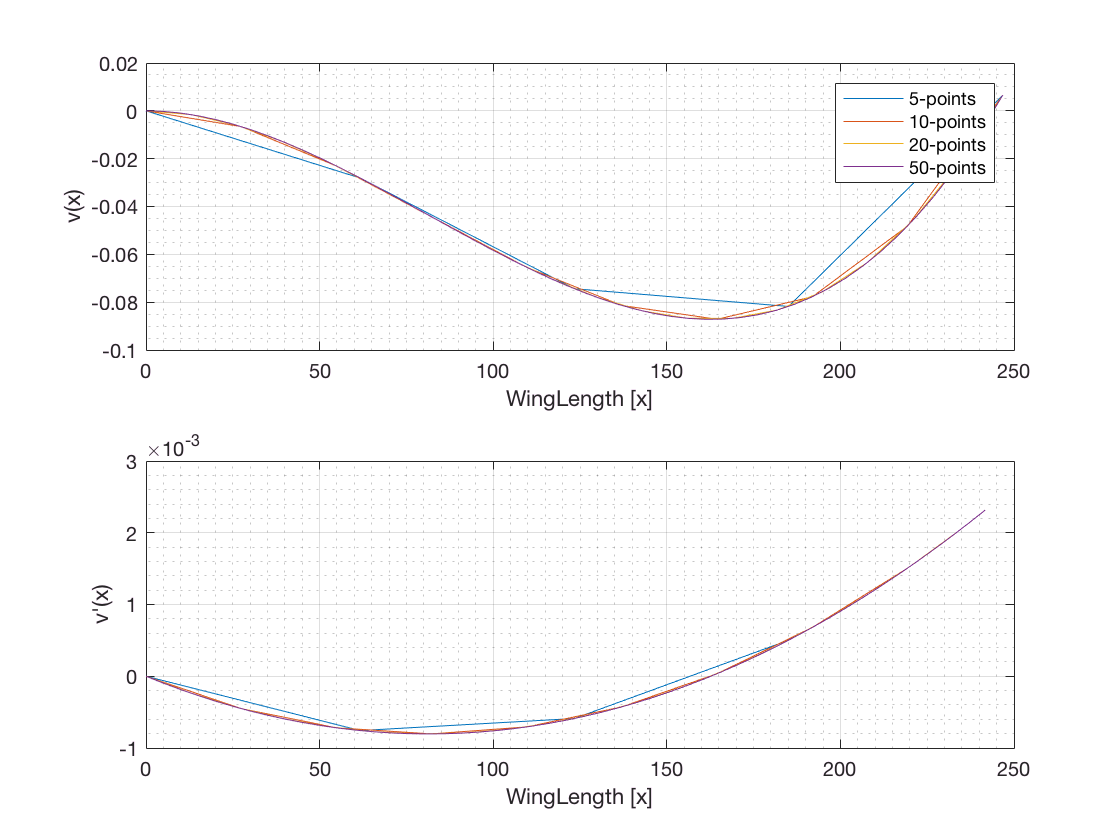

vx5     = vx(x5);
vx10    = vx(x10);
vx20    = vx(x20);
vx50    = vx(x50);
vpx5    = vpx(x5);
vpx10   = vpx(x10);
vpx20   = vpx(x20);
vpx50   = vpx(x50);
figure('Name','Vxp')
subplot(2,1,1)
plot(x5,vx5,x10,vx10,x20,vx20,x50,vx50)
xlabel('WingLength [x]')
ylabel('v(x)')
grid on 
grid minor
legend('5-points','10-points','20-points','50-points')
subplot(2,1,2)
plot(x5,vpx5,x10,vpx10,x20,vpx20,x50,vpx50)
xlabel('WingLength [x]')
ylabel('v''(x)')
grid on 
grid minor

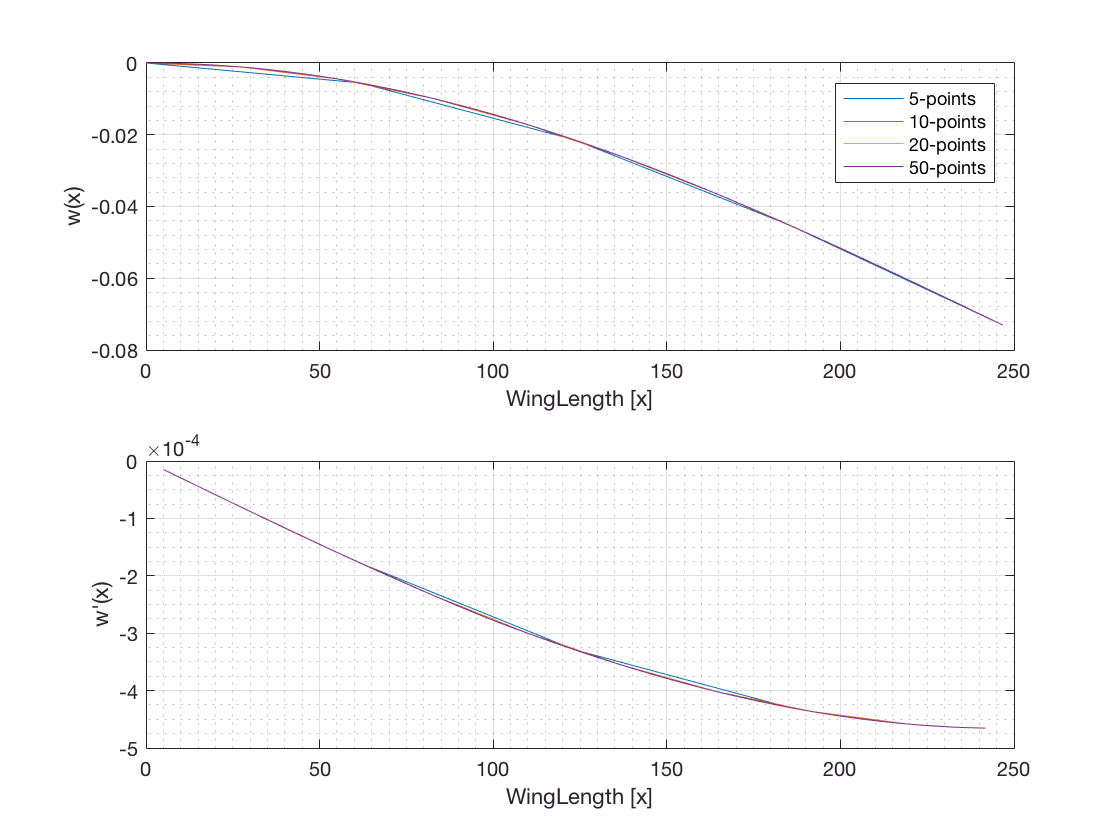

wx5     = wx(x5);
wx10    = wx(x10);
wx20    = wx(x20);
wx50    = wx(x50);
wpx5    = wpx(x5);
wpx10   = wpx(x10);
wpx20   = wpx(x20);
wpx50   = wpx(x50);
figure('Name','Uxp')
subplot(2,1,1)
plot(x5,wx5,x10,wx10,x20,wx20,x50,wx50)
xlabel('WingLength [x]')
ylabel('w(x)')
grid on 
grid minor
legend('5-points','10-points','20-points','50-points')
subplot(2,1,2)
plot(x5,wpx5,x10,wpx10,x20,wpx20,x50,wpx50)
xlabel('WingLength [x]')
ylabel('w''(x)')
grid on 
grid minor

## Timoshenko - Analytical Procedure

The Timoshenko Beam analysis allows for a recycling of previously made computations. 

v       = 0;
Go      = Eo/(2*(1+v));
ks      = 0.75;
Asx     = ks*((Go*TotalWeightArea)/Eo);
Vy_Sym  = (heaviside(x)-heaviside(x-(2*b/5)))*Vy1_Sym + (heaviside(x-(2*b/5))-heaviside(x-b))*Vy2_Sym;
Bz      = -Vy_Sym/(Eo*Asx);
By      = -Vz_Sym/(Eo*Asx);

The Timoshenko Beam analysis results in the same equations and graphical results for the axial displacement $u$. The reader is directed to the previously exposed axial results.

The transverse displacement ($v$) is


$$E_{0}R_{yy}^{*}v(x) = \int{\int(M_{yy}+M_{yy}^t)dx-\int{\{E_{0}R_{yy}^{*}\beta_{z}\}dx+C_{6}x+C_{7}}}\\

v(x) = \frac{ \int{\int(M_{yy}+M_{yy}^t)dx-\int{\{E_{0}R_{yy}^{*}\beta_{z}\}dx+C_{6}x+C_{7}}}}{E_{0}R_{yy}^{*}}$$


C6      = sym('C6');
C7      = sym('C7');
K4      = int(int(Myy_Sym + MyyT)) - int(Eo*Ryy*Bz) + C6*x + C7;
vx      = K4/(Eo*Ryy);
C7      = solve(limit(vx,x,0),C7)

$$C7 = \frac{458643578740602517577874700541917185634917}{12980742146337069071326240823050240}$$

C6      = solve(limit(-(diff(vx)+Bz),x,0),C6)

$$C6 = 0$$

K4      = int(int(Myy_Sym + MyyT)) - int(Eo*Ryy*Bz) + C6*x + C7;
vx      = K4/(Eo*Ryy);

The transverse displacement ($w$) is


$$E_{0}R_{zz}^{*}w(x) = \int{\int-(M_{zz}+M_{zz}^t)dx-\int{\{E_{0}R_{zz}^{*}\beta_{y}\}dx+C_{8}x+C_{9}}}\\

w(x) = \frac{ \int{\int-(M_{zz}+M_{zz}^t)dx-\int{\{E_{0}R_{zz}^{*}\beta_{y}\}dx+C_{8}x+C_{9}}}}{E_{0}R_{zz}^{*}}$$


C8      = sym('C8');
C9      = sym('C9');
K5      = int(int(Mzz_Sym + MzzT)) - int(Eo*Rzz*By) + C8*x + C9;
wx      = K5/(Eo*Rzz);
C9      = solve(limit(wx,x,0),C9)

$$C9 = -\frac{271789630170783271947779164145295739683661697877171}{35318435613731734215794681588274081656995840}$$

C8      = solve(limit(-(diff(wx)+By),x,0),C8)

$$C8 = 0$$

K5      = int(int(Mzz_Sym + MzzT)) - int(Eo*Rzz*By) + C8*x + C9;
wx      = K5/(Eo*Rzz);

## Timoshenko Analytical Graphical Output

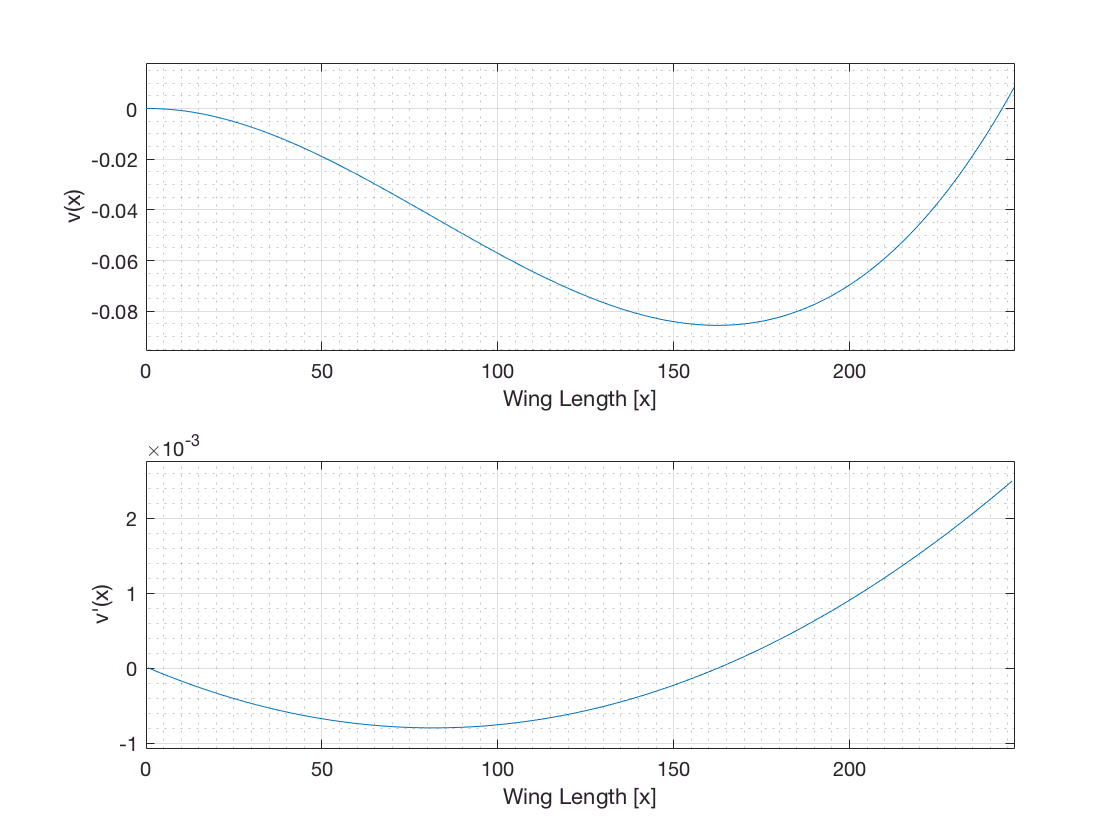

figure('Name','Vx T')
subplot(2,1,1)
ezplot(vx,[0,b])
title('')
xlabel('Wing Length [x]')
ylabel('v(x)')
grid on
grid minor
subplot(2,1,2)
ezplot(diff(vx),[0,b])
title('')
xlabel('Wing Length [x]')
ylabel('v''(x)')
grid on
grid minor

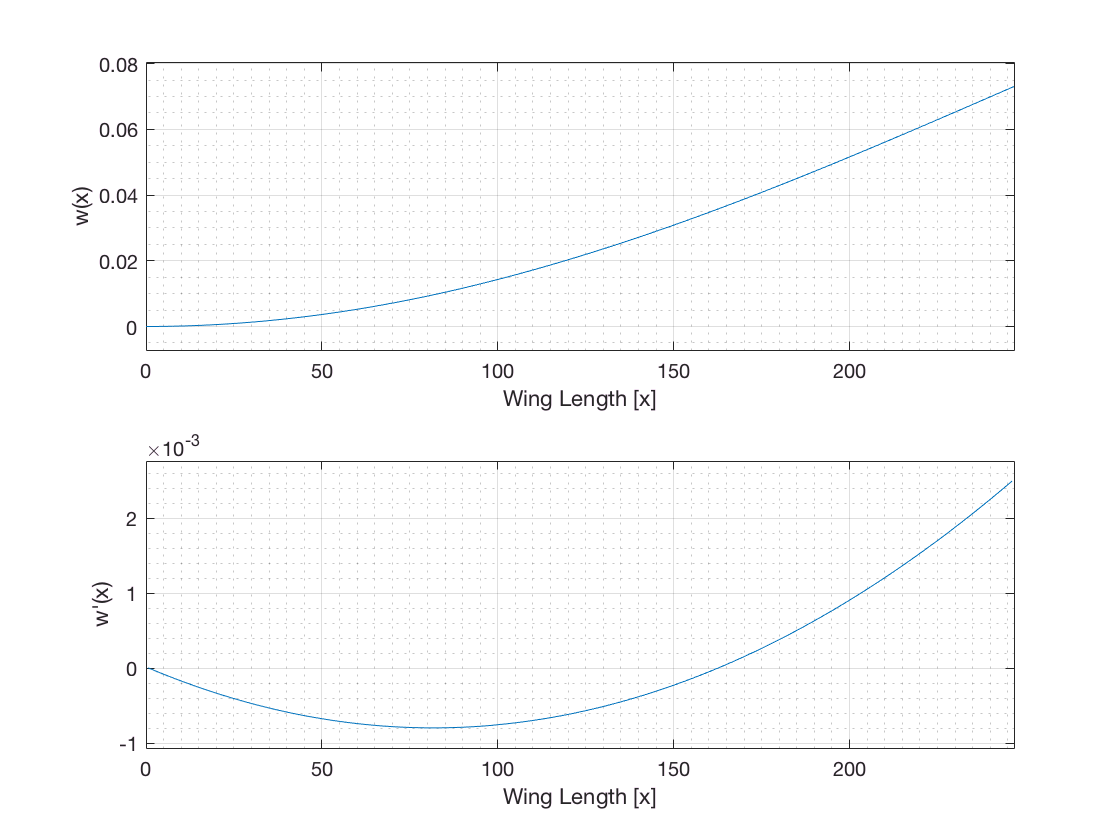

figure('Name','Wx T')
subplot(2,1,1)
ezplot(wx,[0,b])
title('')
xlabel('Wing Length [x]')
ylabel('w(x)')
grid on
grid minor
subplot(2,1,2)
ezplot(diff(vx),[0,b])
title('')
xlabel('Wing Length [x]')
ylabel('w''(x)')
grid on
grid minor

## Timoshenko Discrete Analysis

vpx     = matlabFunction(diff(vx));
vx      = matlabFunction(vx);
wpx     = matlabFunction(diff(wx));
wx      = matlabFunction(wx);

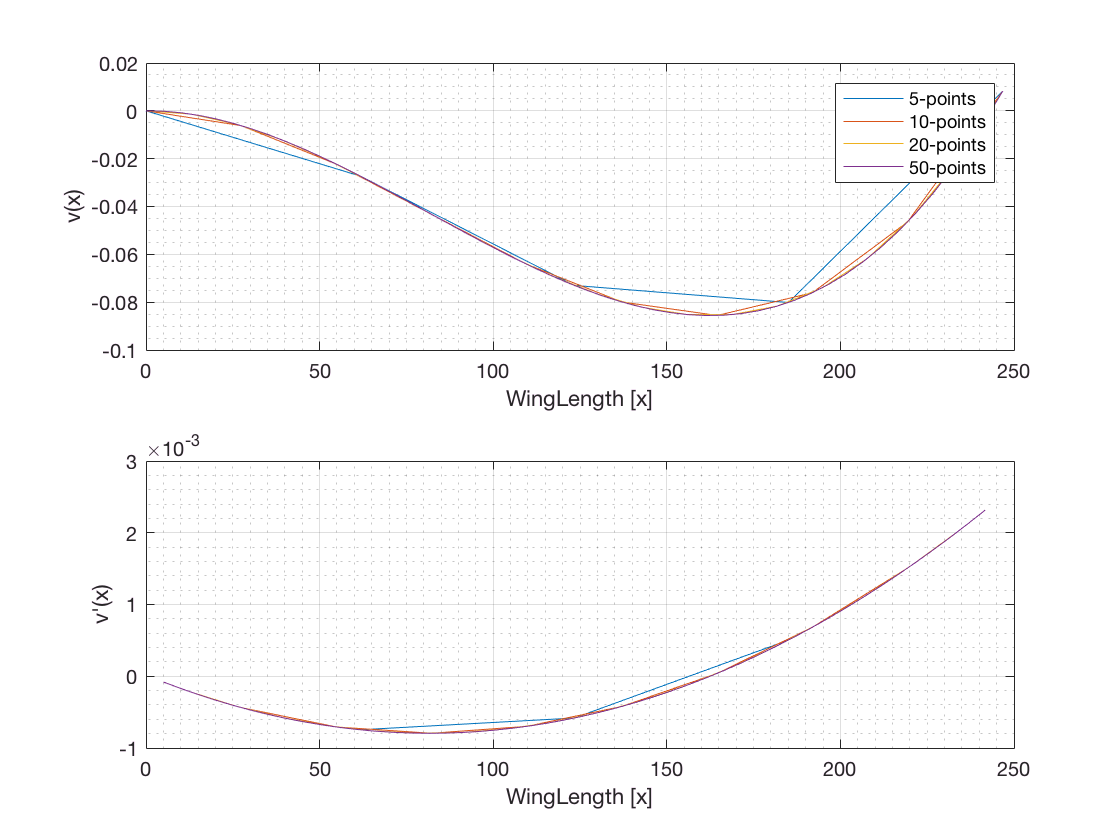

vx5     = vx(x5);
vx10    = vx(x10);
vx20    = vx(x20);
vx50    = vx(x50);
vpx5    = vpx(x5);
vpx10   = vpx(x10);
vpx20   = vpx(x20);
vpx50   = vpx(x50);
figure('Name','Vxp T')
subplot(2,1,1)
plot(x5,vx5,x10,vx10,x20,vx20,x50,vx50)
xlabel('WingLength [x]')
ylabel('v(x)')
grid on 
grid minor
legend('5-points','10-points','20-points','50-points')
subplot(2,1,2)
plot(x5,vpx5,x10,vpx10,x20,vpx20,x50,vpx50)
xlabel('WingLength [x]')
ylabel('v''(x)')
grid on 
grid minor

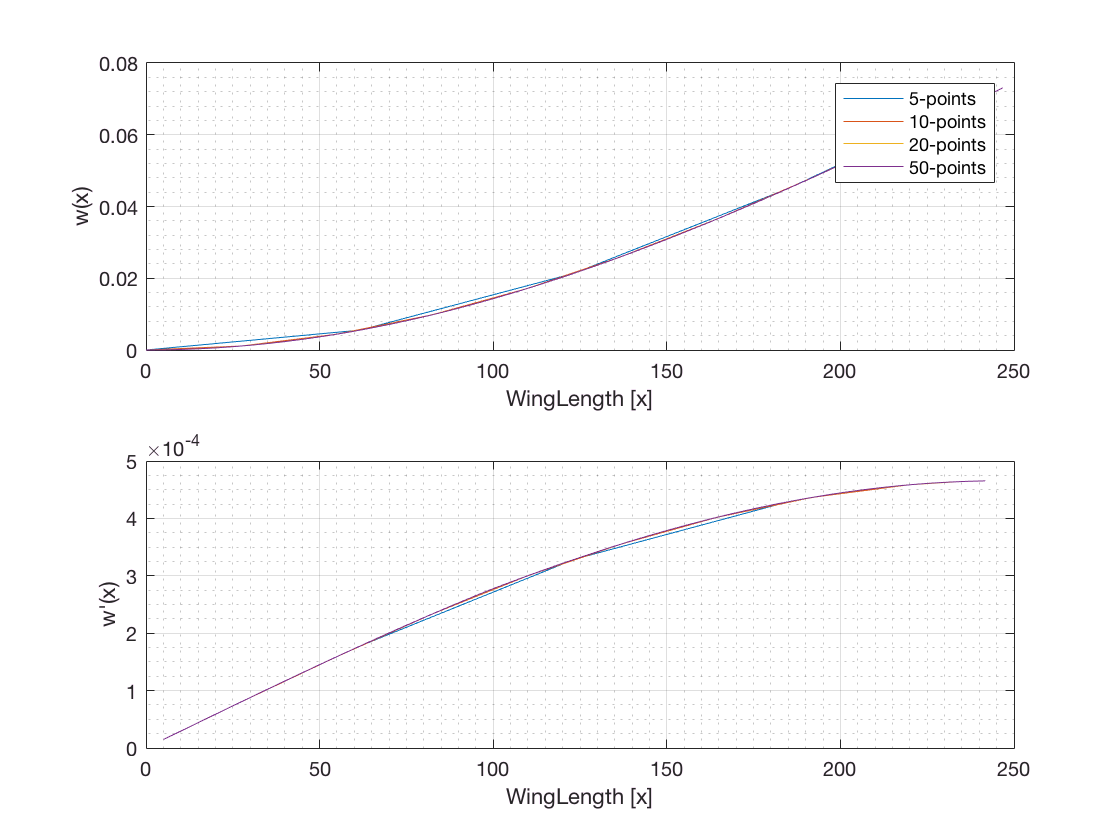

wx5     = wx(x5);
wx10    = wx(x10);
wx20    = wx(x20);
wx50    = wx(x50);
wpx5    = wpx(x5);
wpx10   = wpx(x10);
wpx20   = wpx(x20);
wpx50   = wpx(x50);
figure('Name','Uxp T')
subplot(2,1,1)
plot(x5,wx5,x10,wx10,x20,wx20,x50,wx50)
xlabel('WingLength [x]')
ylabel('w(x)')
grid on 
grid minor
legend('5-points','10-points','20-points','50-points')
subplot(2,1,2)
plot(x5,wpx5,x10,wpx10,x20,wpx20,x50,wpx50)
xlabel('WingLength [x]')
ylabel('w''(x)')
grid on 
grid minor